# Lab: LED Running Lights on the Arty A7-35T with HDL Coder

This lab recreates the classic Vivado *running lights* design using the MathWorks model-based HDL deployment workflow. The design is captured as a Simulink model, VHDL is generated with **HDL Coder**, and the **HDL Workflow Advisor** creates a Xilinx Vivado project. The board-level steps - pin assignment, bitstream generation and JTAG programming - are then completed interactively in the Vivado GUI, exactly like a hand-written RTL project.

**Objectives**

- Build a hardware-ready Simulink model of an 8-bit running-light controller

- Generate VHDL from the model with HDL Coder and inspect the generated code

- Create a Vivado project and run synthesis and implementation from the HDL Workflow Advisor

- Assign board pins, generate a bitstream and program the Digilent Arty A7-35T from the Vivado GUI

**Requirements**

- MATLAB with Simulink, HDL Coder and Fixed-Point Designer (this lab used R2026a)

- Xilinx Vivado 2024.1 installed at `C:\Xilinx\Vivado\2024.1`

- Digilent Arty A7-35T connected over USB

**Note:** in current MATLAB releases the HDL Workflow Advisor offers the *Generic ASIC/FPGA* workflow for boards that are not shipped with a support package (the older *FPGA Turnkey* workflow was removed). This workflow generates code, creates the Vivado project and runs synthesis and implementation for analysis - the final board-specific steps are done in Vivado, and this lab walks through all of them. Section 13 shows the alternative: registering the Arty as a custom board so the workflow handles pins and programming for you.

projDir = 'C:\demo\hdl_coder_led_blinking';
cd(projDir)

## 1. The Simulink model

1.1 Open the model `flash_led.slx`. The root level contains the design-under-test (DUT) subsystem `flash_led_top` and a Scope for simulation. Only the contents of the DUT subsystem become HDL - the Scope stays in the simulation world.

open_system('flash_led')

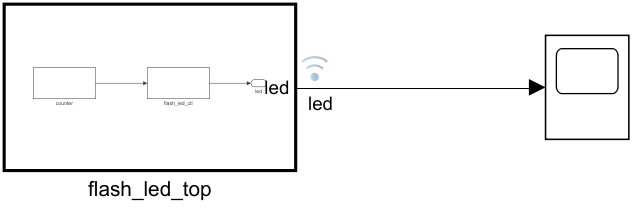

1.2 Inside `flash_led_top` the design is split exactly like the hand-written VHDL reference: a `counter` subsystem generates a one-cycle `tick` pulse, and `flash_led_ctl` rotates the 8-bit LED pattern on every tick. The `led` output port is a `uint8` whose bits drive the eight board LEDs.

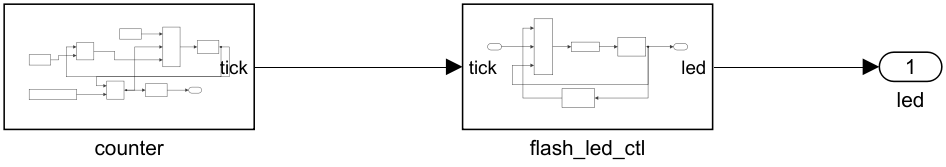

1.3 The `counter` subsystem is a free-running counter with synchronous wrap: when the count reaches `MAX_COUNT-1` a Switch reloads the register with zero and the comparison result is registered to produce a clean one-cycle `tick` pulse. The counter uses a 23-bit unsigned fixed-point type (`fixdt(0,23,0)`), the smallest width that holds `MAX_COUNT-1 = 4999999`. With a 100 MHz clock and `MAX_COUNT = 5000000` the tick rate is 20 Hz.

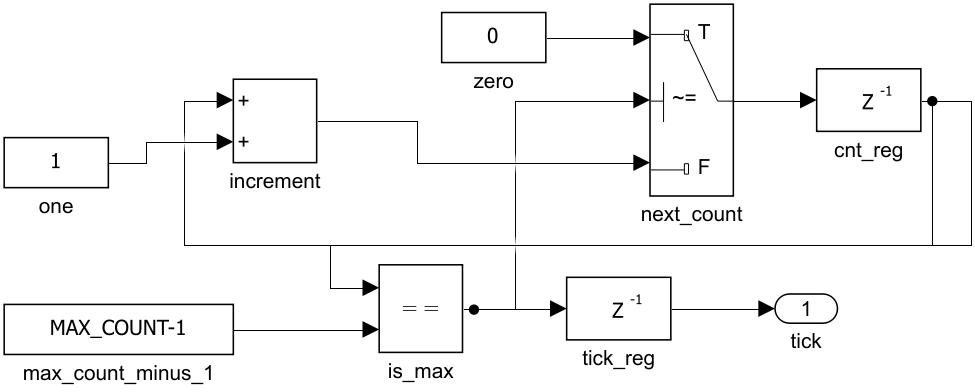

1.4 The `flash_led_ctl` subsystem holds the LED pattern in a Delay register with initial value 1 (LED0 lit). A **Bit Rotate** block (HDL Coder library) rotates the pattern left by one position, and a Switch updates the register only when `tick` is high - the direct model-level equivalent of the VHDL `if tick = '1' then pattern <= pattern(6 downto 0) & pattern(7)` construct. A Signal Specification block pins the loop data type to `uint8`.

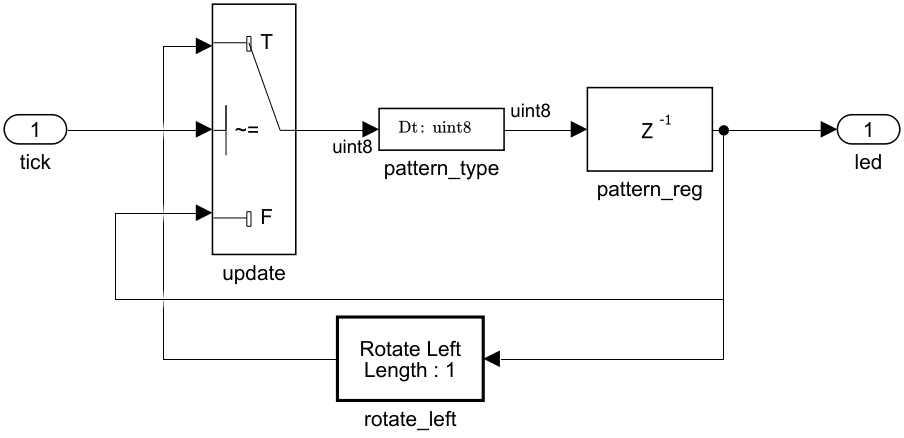

1.5 `MAX_COUNT` is a model workspace variable, so the shift speed can be changed without editing the diagram. The value stored in the model is the hardware value.

mws = get_param('flash_led','ModelWorkspace');
disp(getVariable(mws,'MAX_COUNT'))

     5000000



## 2. Configure the model for HDL code generation

2.1 `hdlsetup` applies the recommended solver and code generation settings for HDL: a fixed-step discrete solver, inlined parameters and an ASIC/FPGA hardware device type. The fundamental sample time is set to 10 ns so one simulation step corresponds to one 100 MHz clock cycle. Open **Modeling > Model Settings** and check the **Solver** pane.

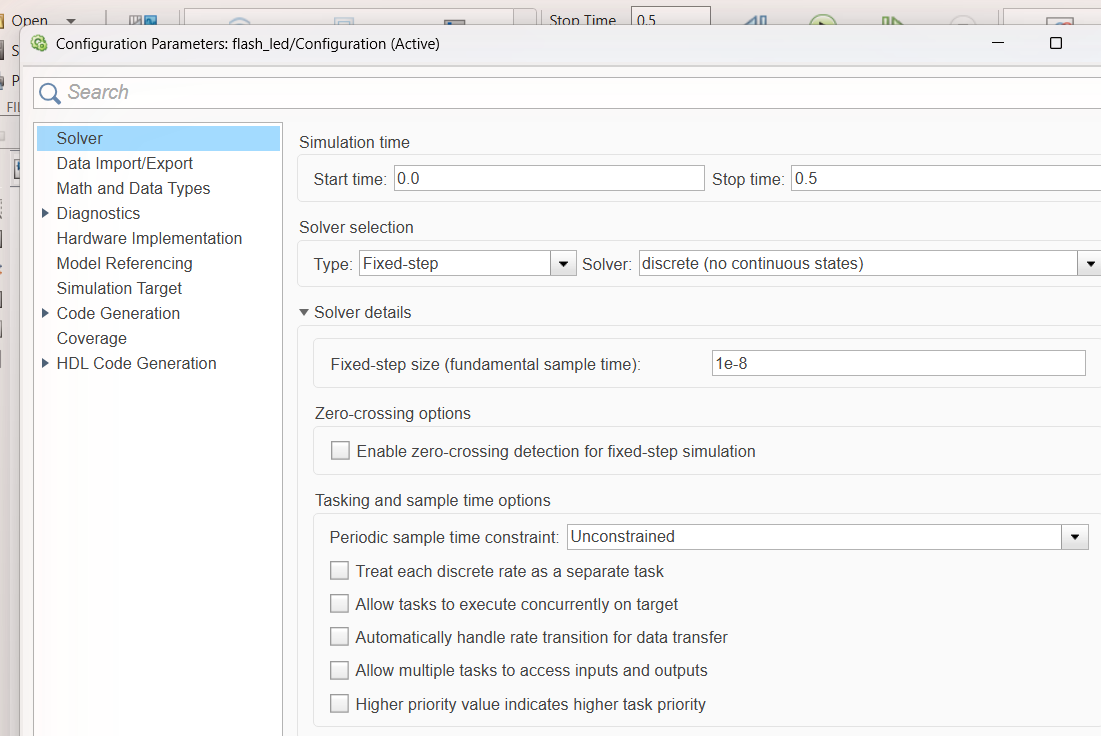

2.2 On the **HDL Code Generation** pane select `VHDL` as the target language and generate code for the DUT subsystem `flash_led/flash_led_top`.

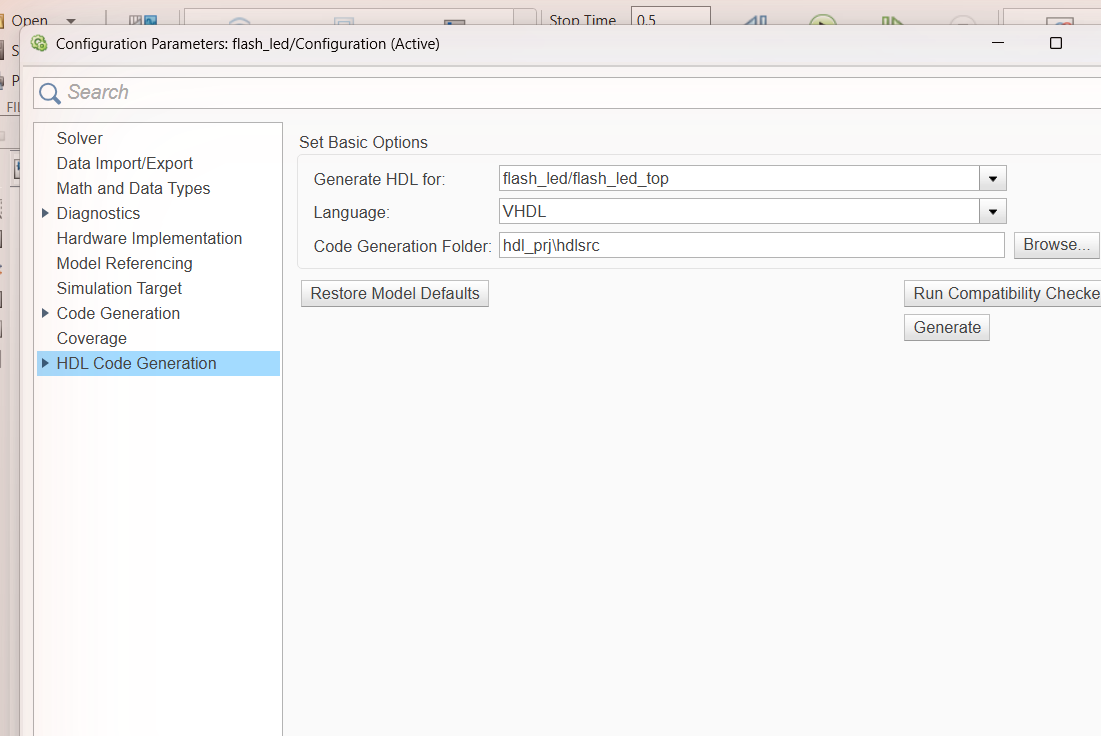

2.3 On the **HDL Code Generation > Target** pane select the *Generic ASIC/FPGA* workflow, the *Xilinx Vivado* synthesis tool and the Arty A7-35T FPGA: family `Artix7`, device `xc7a35ti`, package `csg324`, speed `-1L`, with a target frequency of 100 MHz.

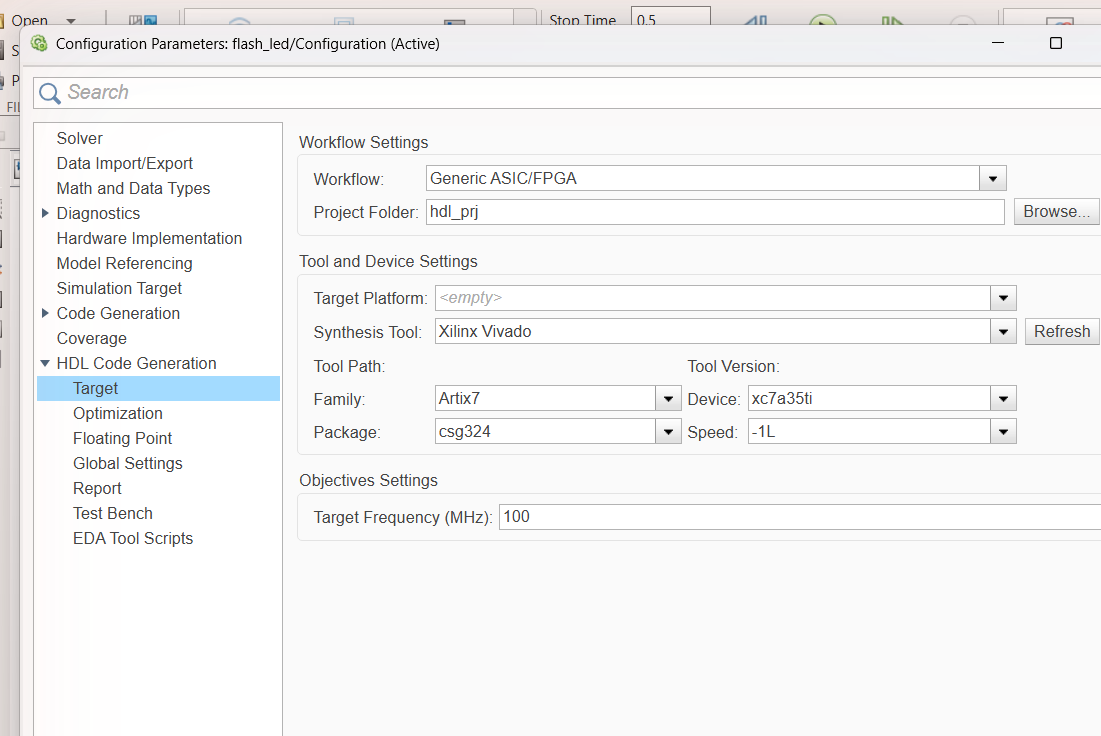

2.4 **Important - remove the clock-enable ports.** By default HDL Coder adds two framework ports to the generated top level: a `clk_enable` input that gates every register and a `ce_out` output that forwards the enable to downstream modules. They are not real board I/O: `clk_enable` must be tied high and `ce_out` left open, and if the generated top level is used directly as the Vivado top module they show up as unassignable pins and the bitstream fails, as below.

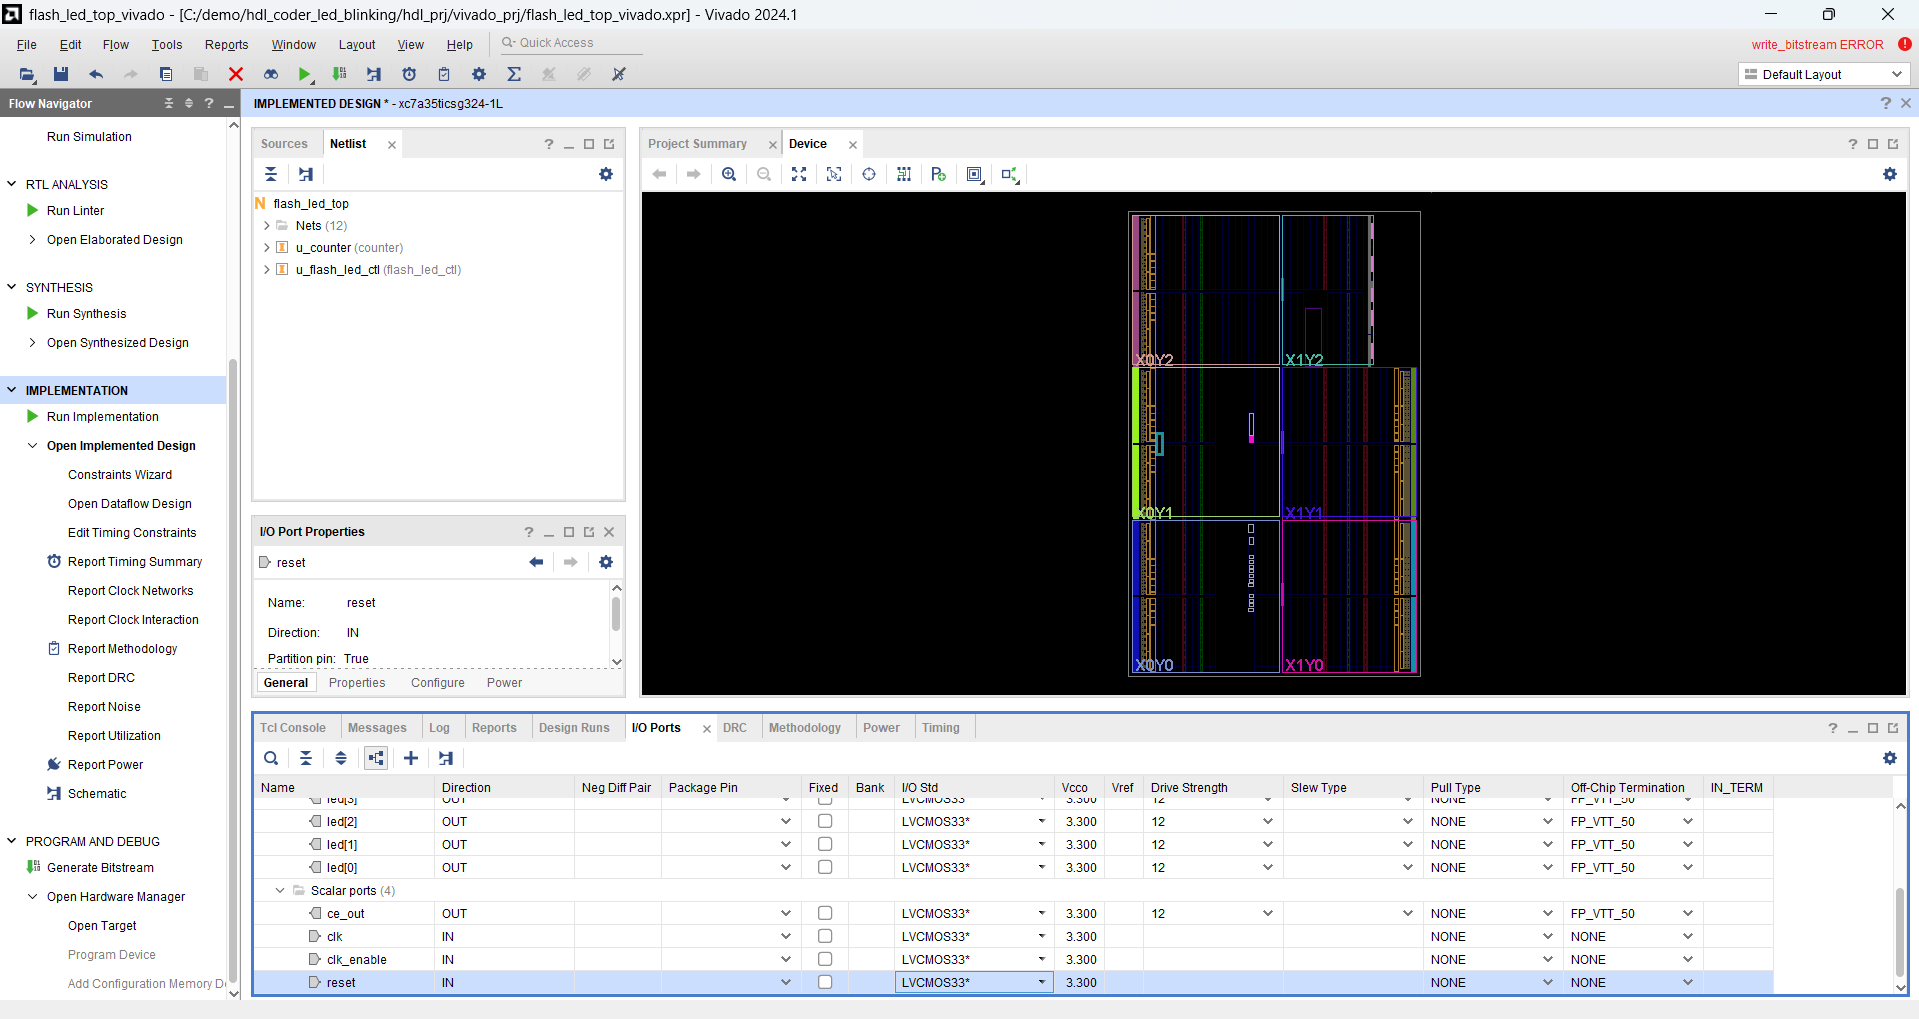

For a single-rate design like this one, enable **Minimize clock enables** on the **HDL Code Generation > Global Settings > Ports** tab (or search the configuration dialog for it). The regenerated entity then has only `clk`, `reset` and `led` - exactly the ports of the hand-written reference design. Leave *Minimize global resets* off so the `reset` port (push button BTN0) is kept.

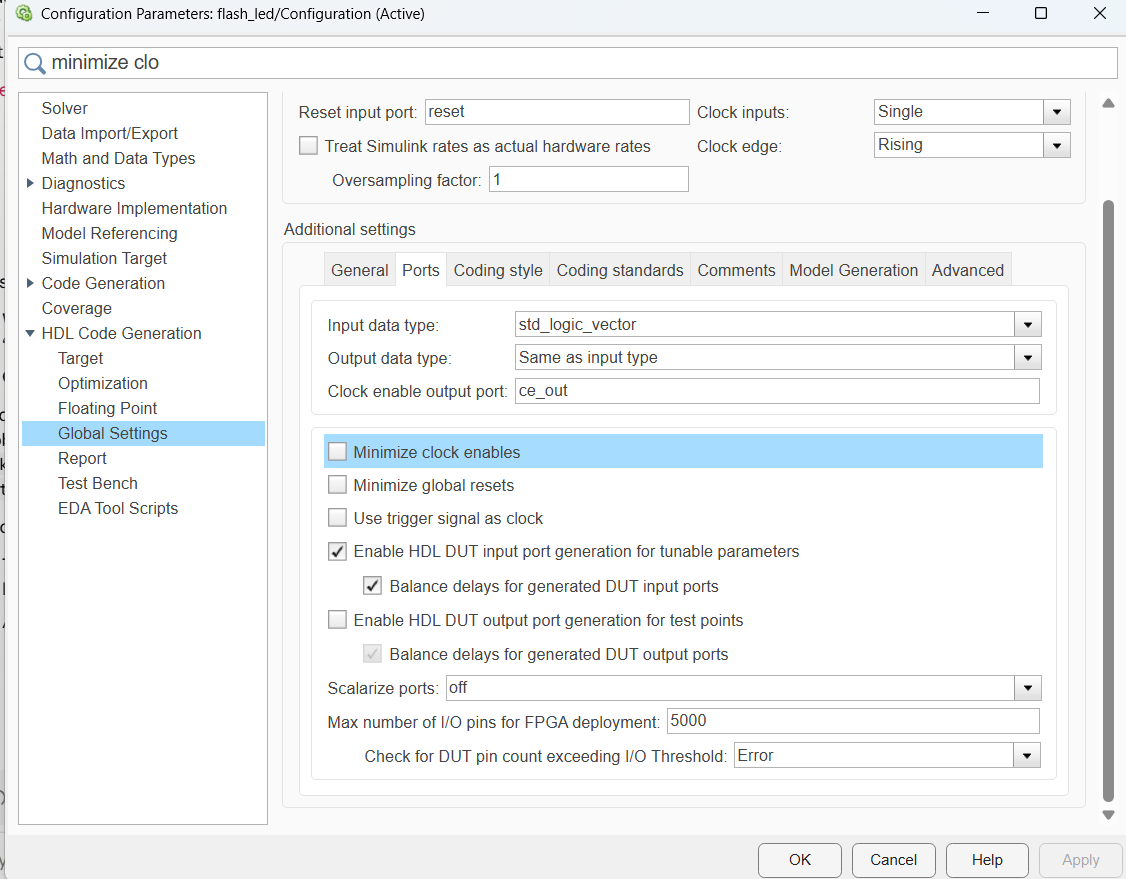

2.5 The same configuration can be applied from the command line. `hdlsetuptoolpath` registers the Vivado installation with HDL Coder and must be run once per MATLAB session.

hdlsetup('flash_led')

### The configuration parameter values use the recommended settings for HDL code generation and does not need any modification as a part of hdlsetup. Please refer to hdlsetup document for best practices on model settings.


hdlset_param('flash_led','TargetLanguage','VHDL','HDLSubsystem','flash_led/flash_led_top','TargetFrequency',100)
hdlset_param('flash_led','SynthesisTool','Xilinx Vivado','SynthesisToolChipFamily','Artix7','SynthesisToolDeviceName','xc7a35ti','SynthesisToolPackageName','csg324','SynthesisToolSpeedValue','-1L')
hdlset_param('flash_led','MinimizeClockEnables','on')
hdlsetuptoolpath('ToolName','Xilinx Vivado','ToolPath','C:\Xilinx\Vivado\2024.1\bin\vivado.bat');

Prepending following Xilinx Vivado path(s) to the system path:
C:\Xilinx\Vivado\2024.1\bin
Prepending following Xilinx Vivado path(s) to the system path:
C:\Xilinx\Vivado\2024.1\bin\..\lib\win64.o


## 3. Simulate the design

3.1 At the hardware value of `MAX_COUNT` the LED only shifts every 50 ms of simulated time, so for a quick functional check lower `MAX_COUNT` to 10 and simulate 3 us. The logged `led` signal shows the one-hot pattern 1, 2, 4, ... 128 rotating left and wrapping - the same behaviour the board will show, just faster.

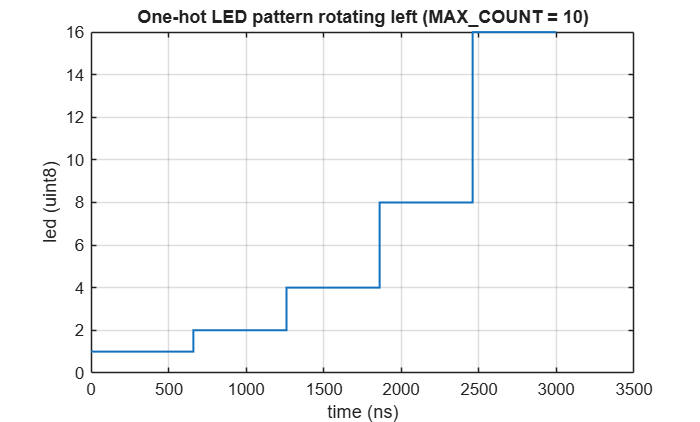

assignin(mws,'MAX_COUNT',10)
out = sim('flash_led','StopTime','3e-6');
led = out.logsout.getElement('led').Values;
stairs(led.Time*1e9,double(led.Data),'LineWidth',1.2)
xlabel('time (ns)')
ylabel('led (uint8)')
title('One-hot LED pattern rotating left (MAX\_COUNT = 10)')
grid on

assignin(mws,'MAX_COUNT',5000000)

3.2 The same result can be viewed interactively: press **Run** in the Simulink toolstrip and open the Scope.

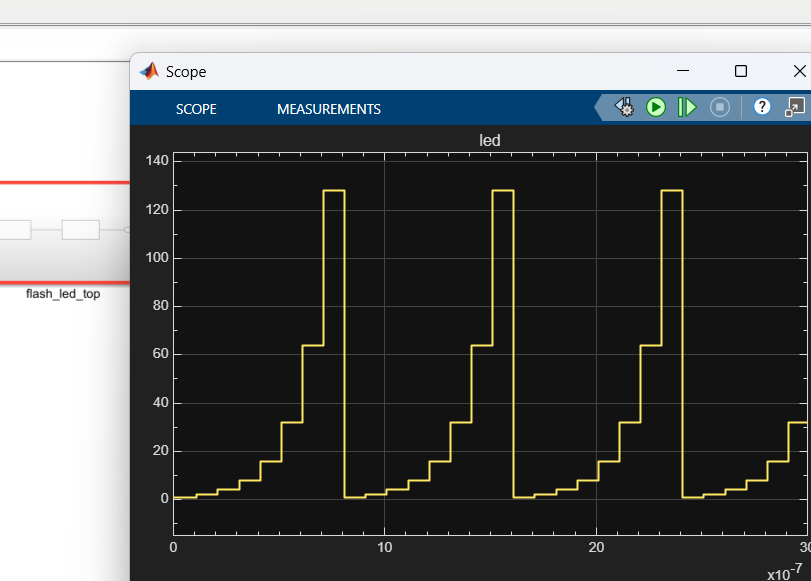

## 4. Open the HDL Workflow Advisor

4.1 In the Simulink toolstrip open the **Apps** tab and click **HDL Coder** (under *Code Generation*).

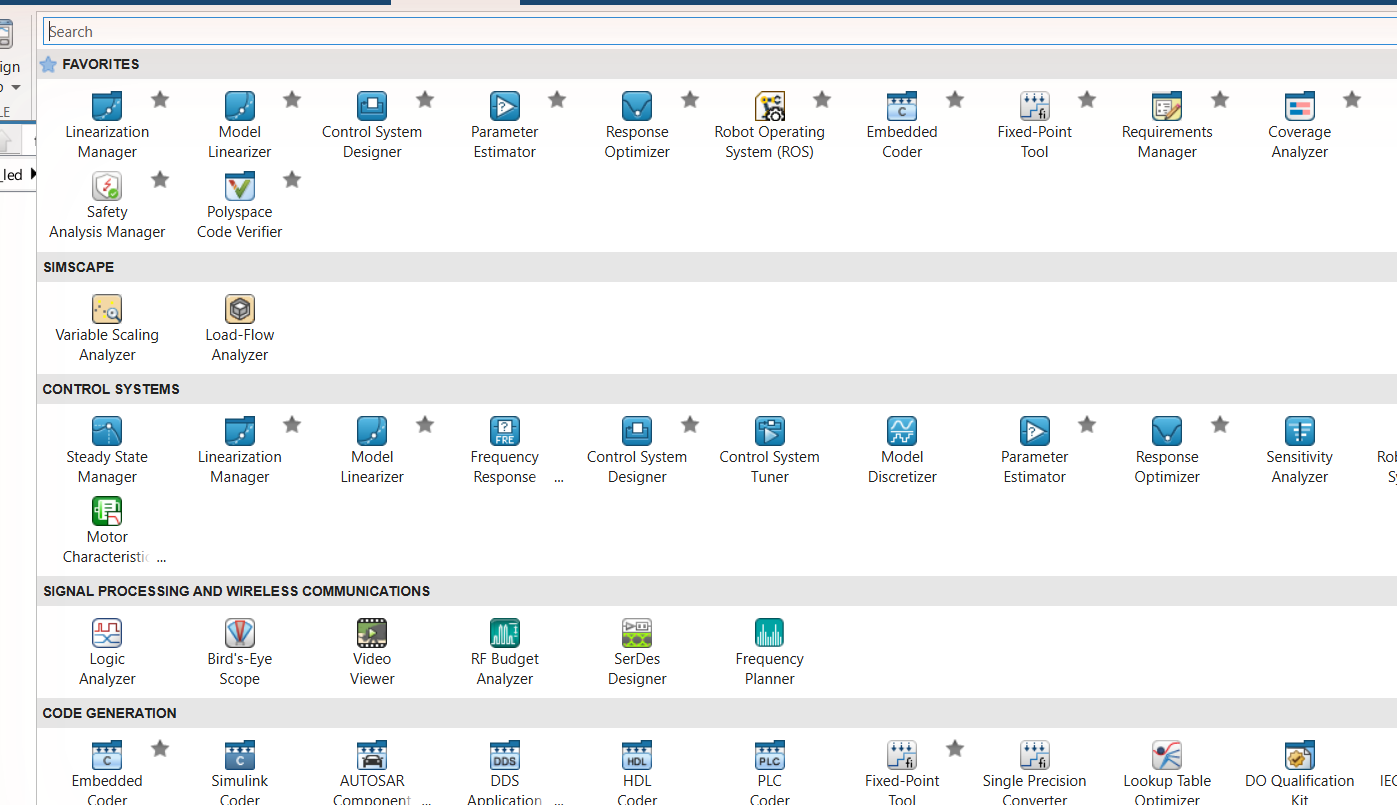

4.2 The **HDL Code** tab appears with `flash_led_top` preselected as the code-generation target. Click **Workflow Advisor**.

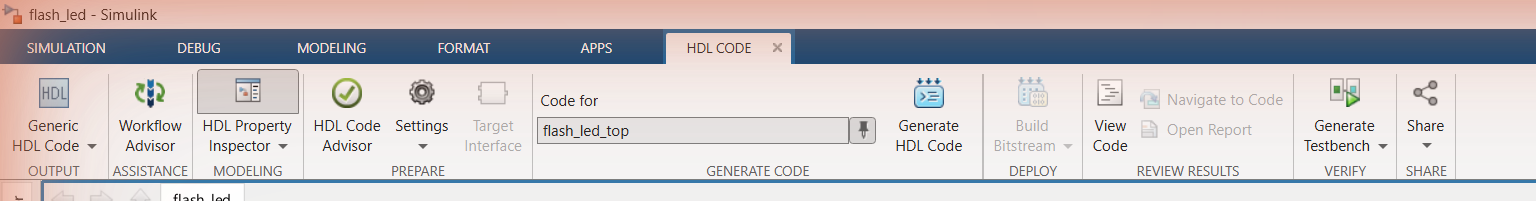

4.3 The HDL Workflow Advisor opens with four task groups: Set Target, Prepare Model For HDL Code Generation, HDL Code Generation, and FPGA Synthesis and Analysis. The advisor can also be opened from the command line with `hdladvisor('flash_led/flash_led_top')`.

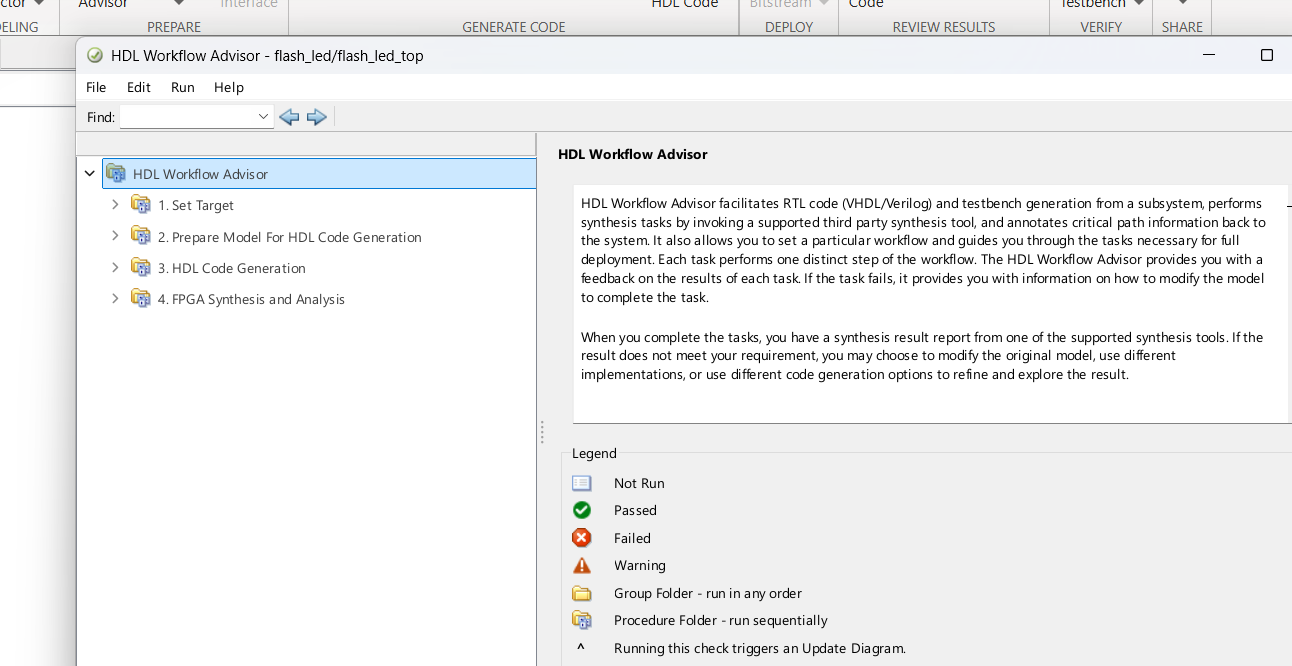

## 5. Set the target device and frequency

5.1 Task **1.1 Set Target Device and Synthesis Tool** is prefilled from the model settings of section 2: workflow *Generic ASIC/FPGA*, tool *Xilinx Vivado* (version 2024.1 is detected from the registered tool path), device `xc7a35ti csg324 -1L` and project folder `hdl_prj`. Click **Run This Task**. If the project folder already exists the advisor asks whether to reuse it - answer **Yes**.

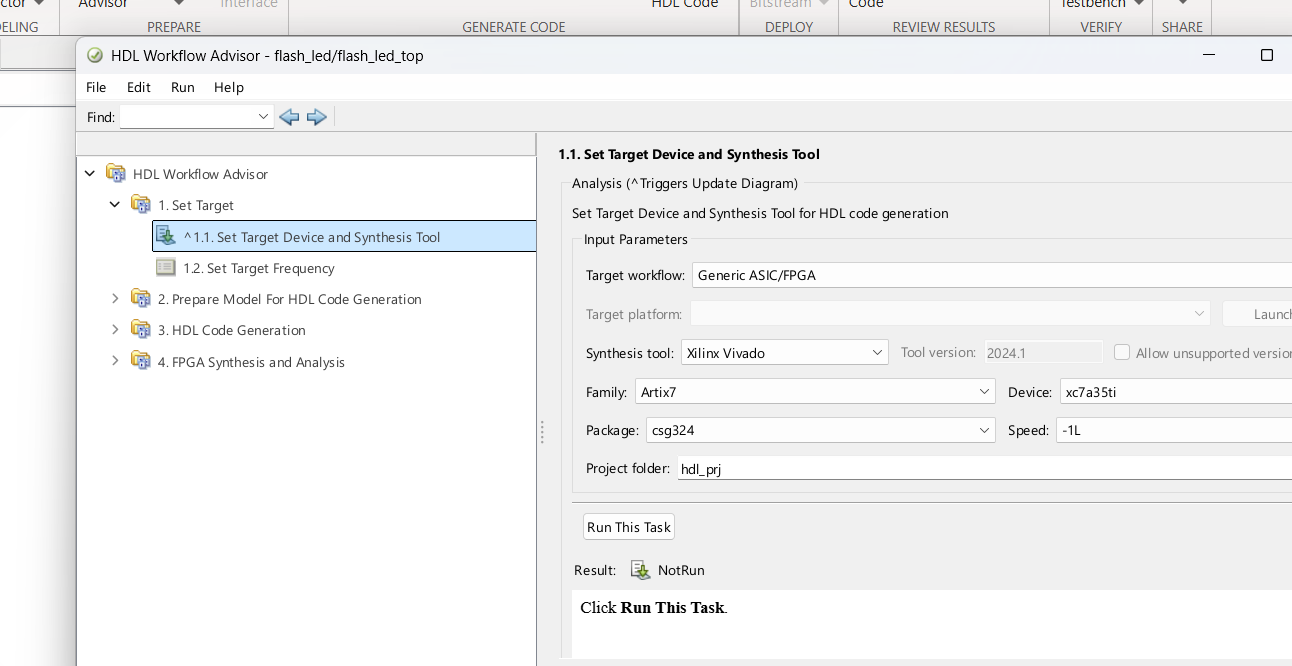

5.2 The task finishes with a green check mark.

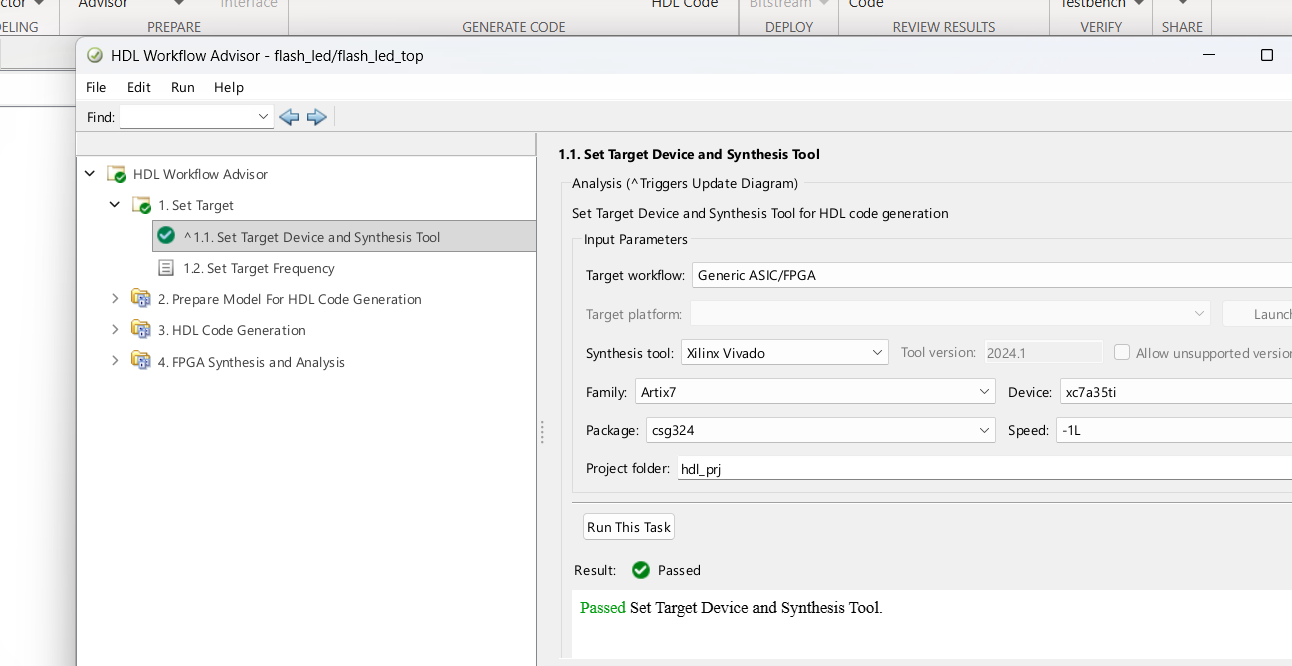

5.3 Task **1.2 Set Target Frequency** shows the 100 MHz target taken from the model. Run it. HDL Coder later writes this as a `create_clock` constraint for the Vivado project.

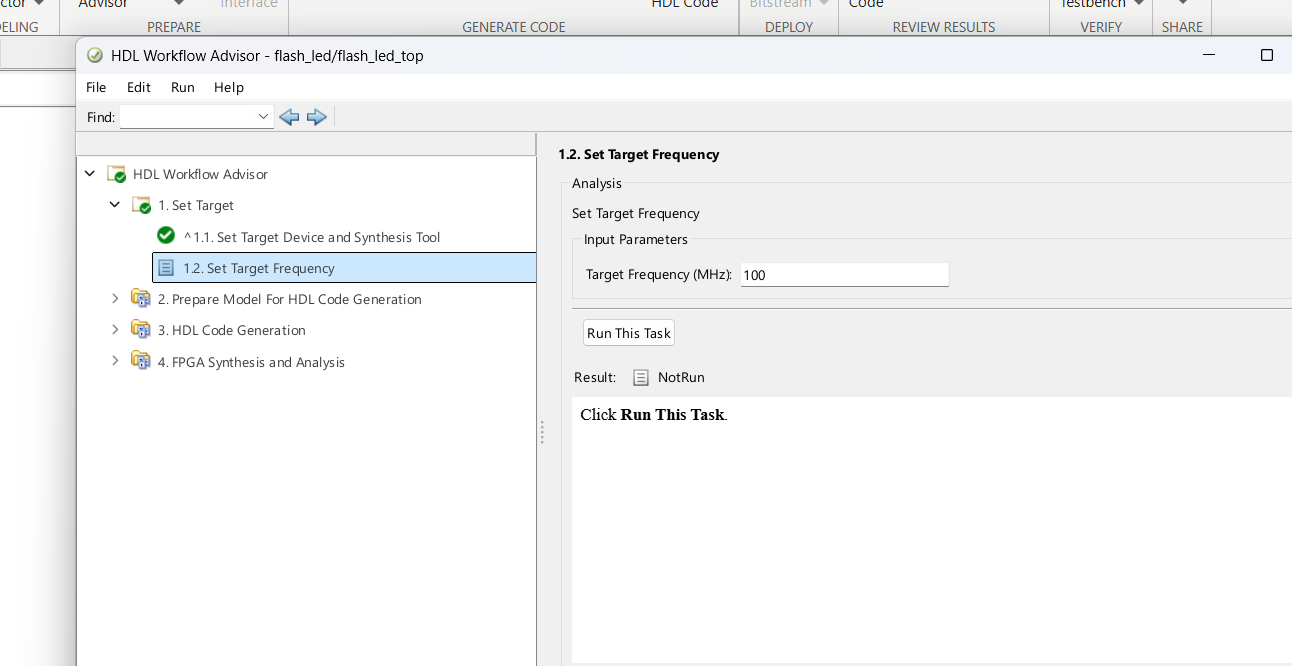

## 6. Generate the VHDL code

6.1 The tasks in groups **2. Prepare Model For HDL Code Generation** and **3. HDL Code Generation** check the model and generate the VHDL. Run them in order (or right-click a task and choose *Run to Selected Task*). When code generation completes, the Code Generation Report opens: three VHDL files are produced in `hdl_prj\hdlsrc\flash_led`, one per subsystem - exactly mirroring the structure of the hand-written reference design: `counter.vhd`, `flash_led_ctl.vhd` and `flash_led_top.vhd`.

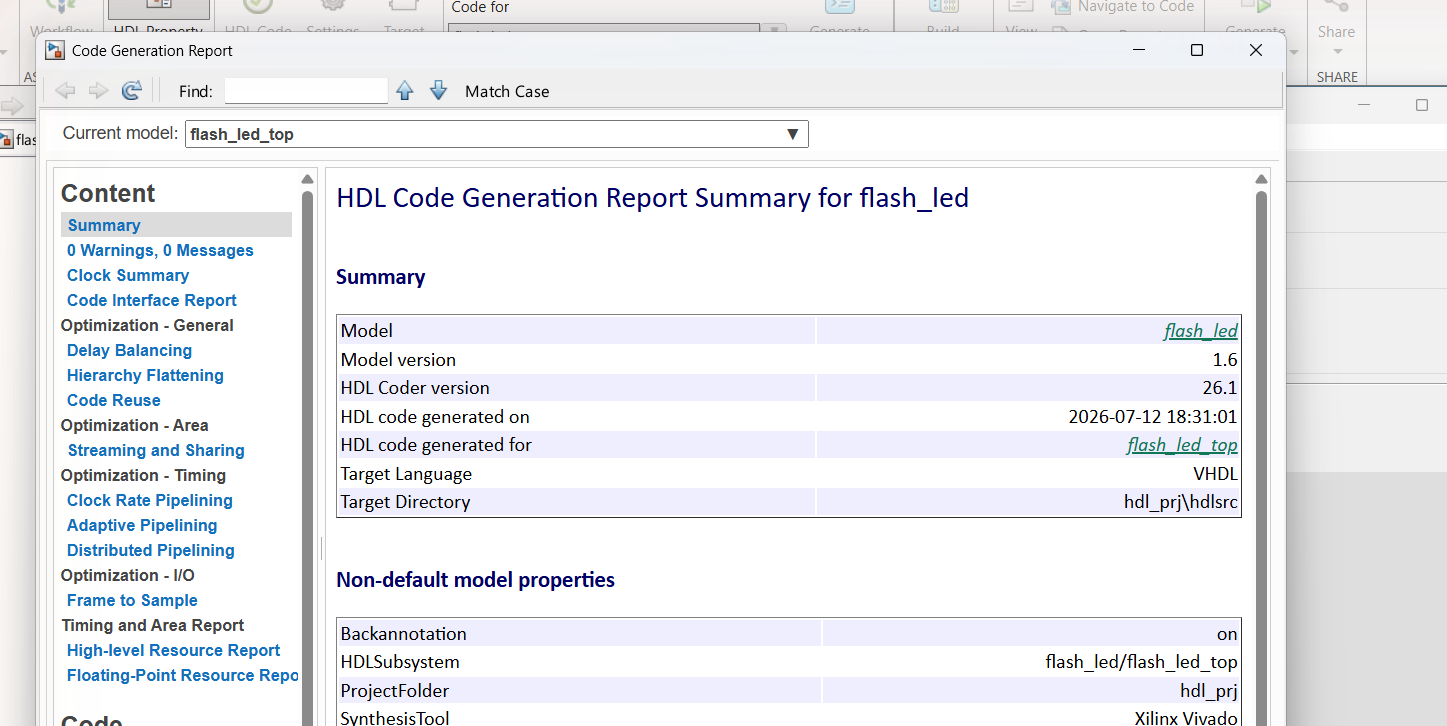

6.2 With *Minimize clock enables* on, the generated top-level entity has exactly the three board-level ports and nothing else.

gen = fileread(fullfile(projDir,'hdl_prj','hdlsrc','flash_led','flash_led_top.vhd'));
k1 = strfind(gen,'ENTITY flash_led_top IS');
k2 = strfind(gen,'END flash_led_top;');
disp(gen(k1:k2+17))

ENTITY flash_led_top IS
  PORT( clk                               :   IN    std_logic;
        reset                             :   IN    std_logic;
        led                               :   OUT   std_logic_vector(7 DOWNTO 0)  -- uint8
        );
END flash_led_top;


## 7. Create the Vivado project and run synthesis in the Advisor

7.1 Run task **4.1 Create Project** with its default settings. HDL Coder creates a Vivado project at `hdl_prj\vivado_prj\flash_led_top_vivado.xpr` containing the three generated VHDL files and the 100 MHz clock constraint.

7.2 Optionally run the tasks under **4.2 Perform Synthesis and P/R** (untick *Skip this task* on 4.2.2 first). These runs are for analysis - the advisor parses the utilization and timing results back into MATLAB: the running light needs just 31 LUTs and 32 flip-flops, and the 100 MHz clock is met with more than 5 ns of slack.

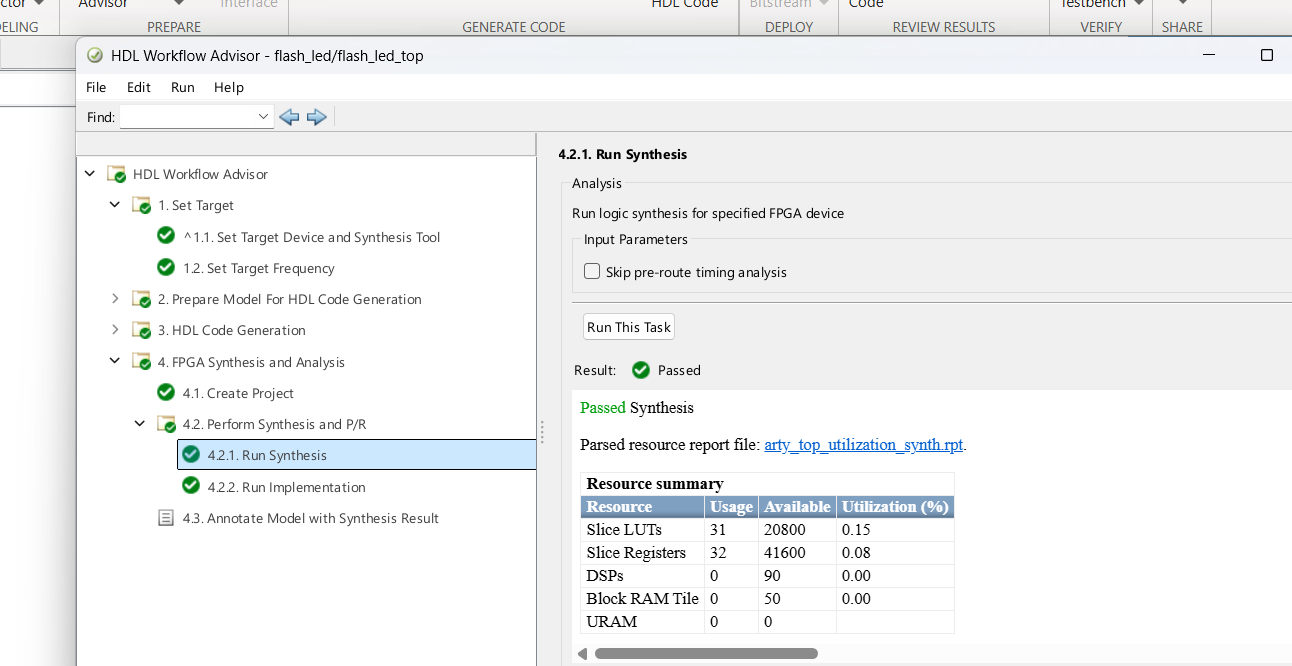

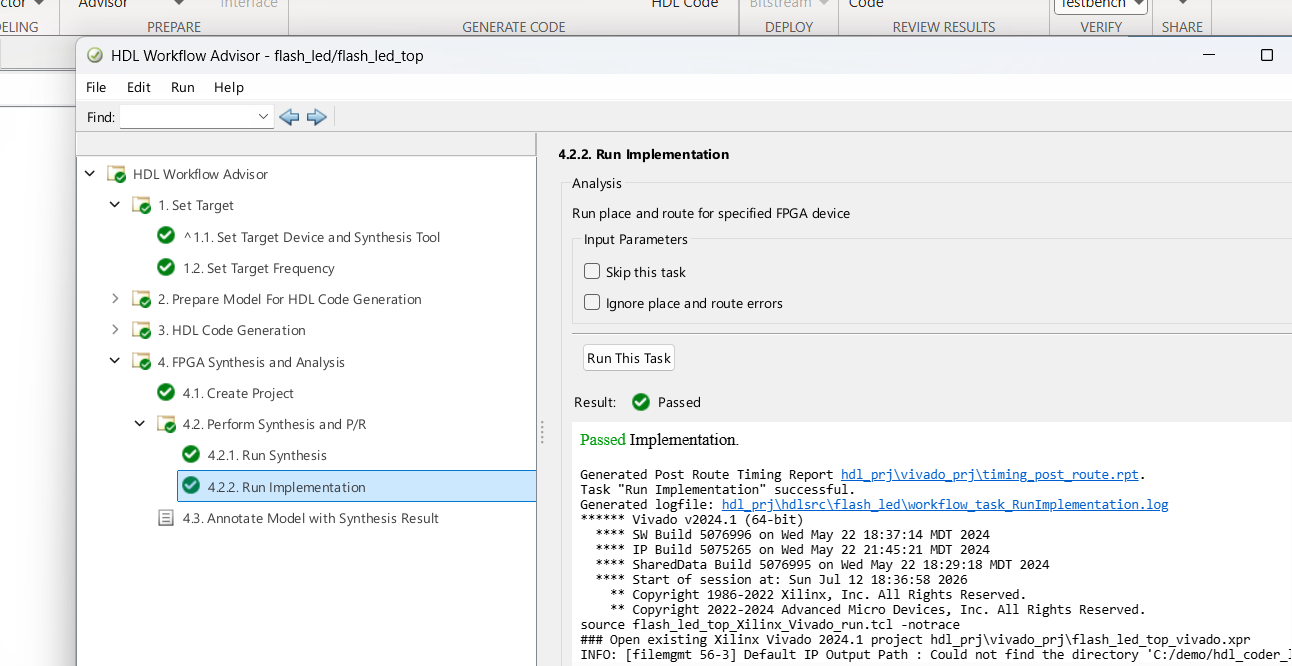

**Why the extra Vivado steps below?** The Generic ASIC/FPGA workflow stops here by design: it knows the FPGA device but not the board, so it has no pin locations, and its synthesis run is configured for analysis (out-of-context) rather than for a full bitstream. Sections 8-11 finish the job in the Vivado GUI: assign pins, switch the synthesis run to a full-design run, generate the bitstream and program the board. Section 13 shows how registering a custom board removes sections 8-11 entirely.

## 8. Assign the board pins in Vivado

8.1 Open the generated project in Vivado: **File > Open Project** and select `hdl_prj\vivado_prj\flash_led_top_vivado.xpr` (or double-click the file).

8.2 In the Flow Navigator click **Open Synthesized Design**, then open **Window > I/O Ports**. Assign the *Package Pin* and set *I/O Std* to `LVCMOS33` for every port, then tick *Fixed*:

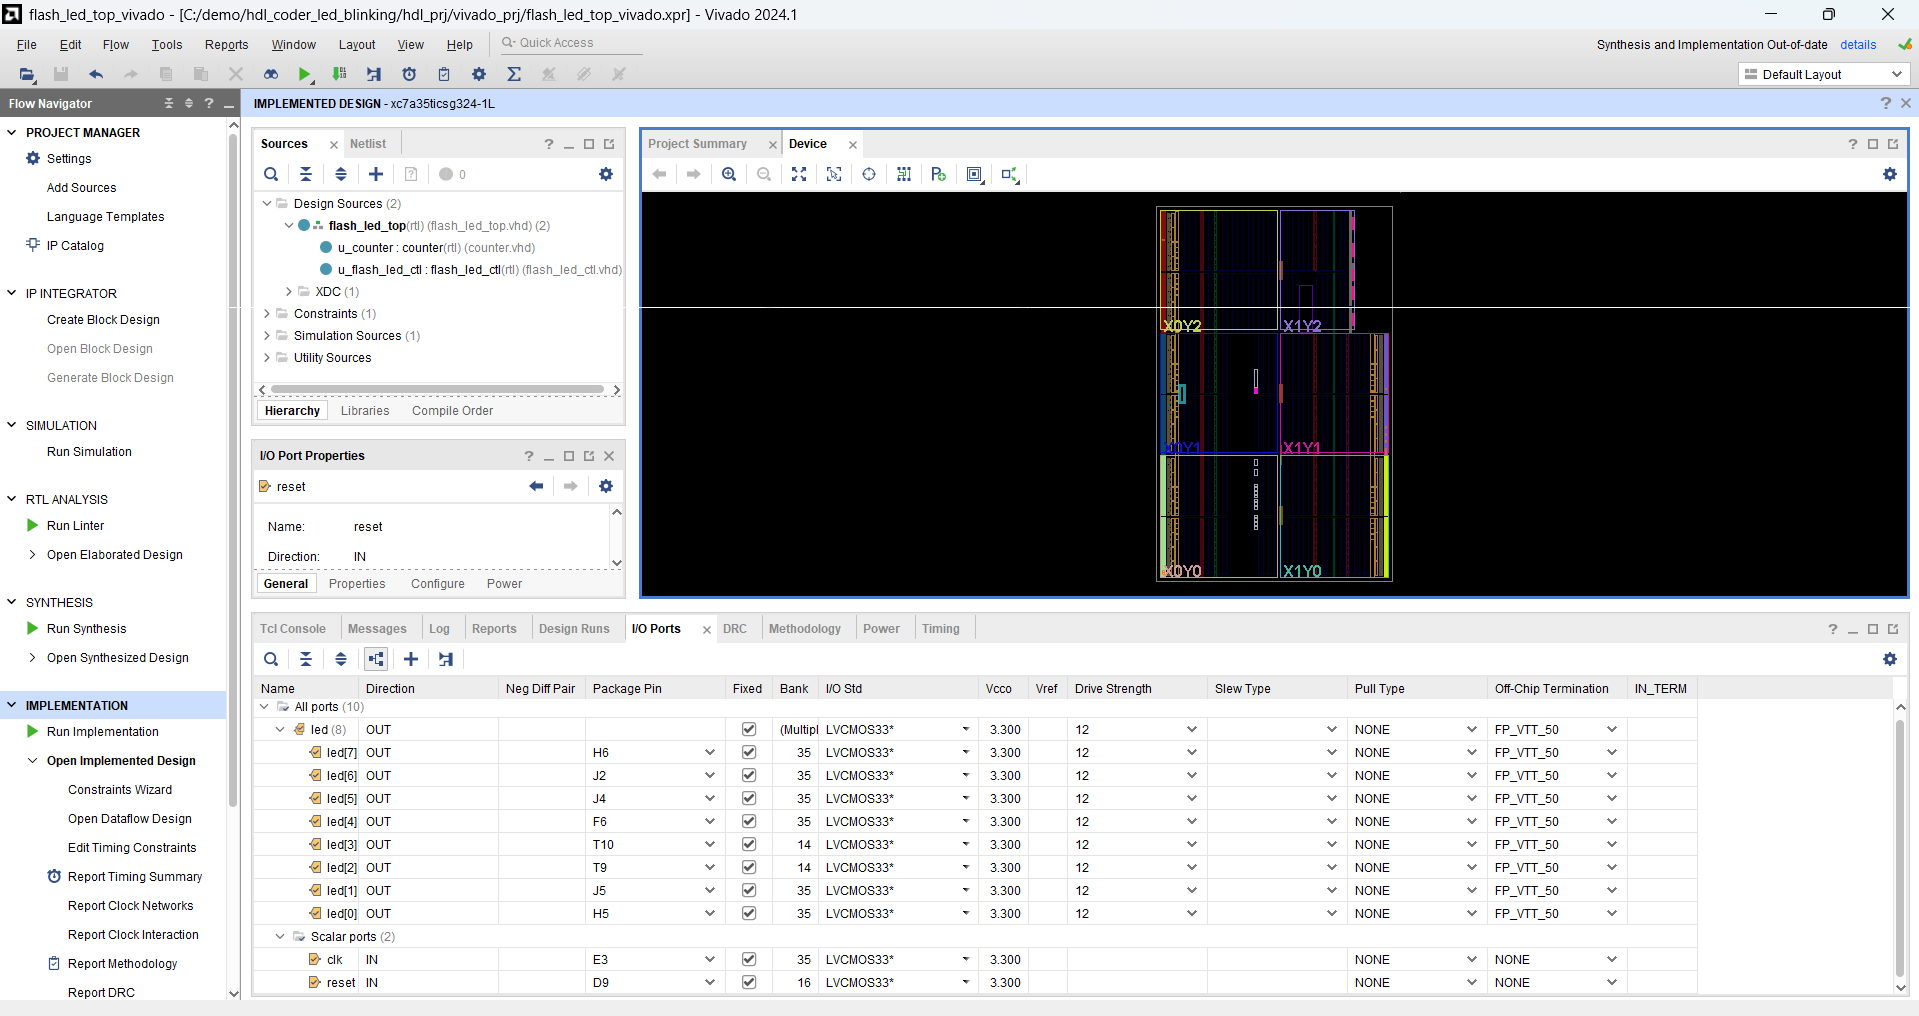

8.3 Press **Ctrl+S** to save the constraints. Vivado asks for a constraints file name (for example `flash_led_top_vivado`) and adds the pin assignments to the project as an XDC file.

## 9. Switch synthesis to a full-design run

9.1 HDL Coder creates the synthesis run in **out-of-context (OOC) mode** - right for module analysis, but it skips I/O buffer insertion, so a bitstream build fails in the placer with *Unbuffered IOs* / *Placer could not place all instances*:

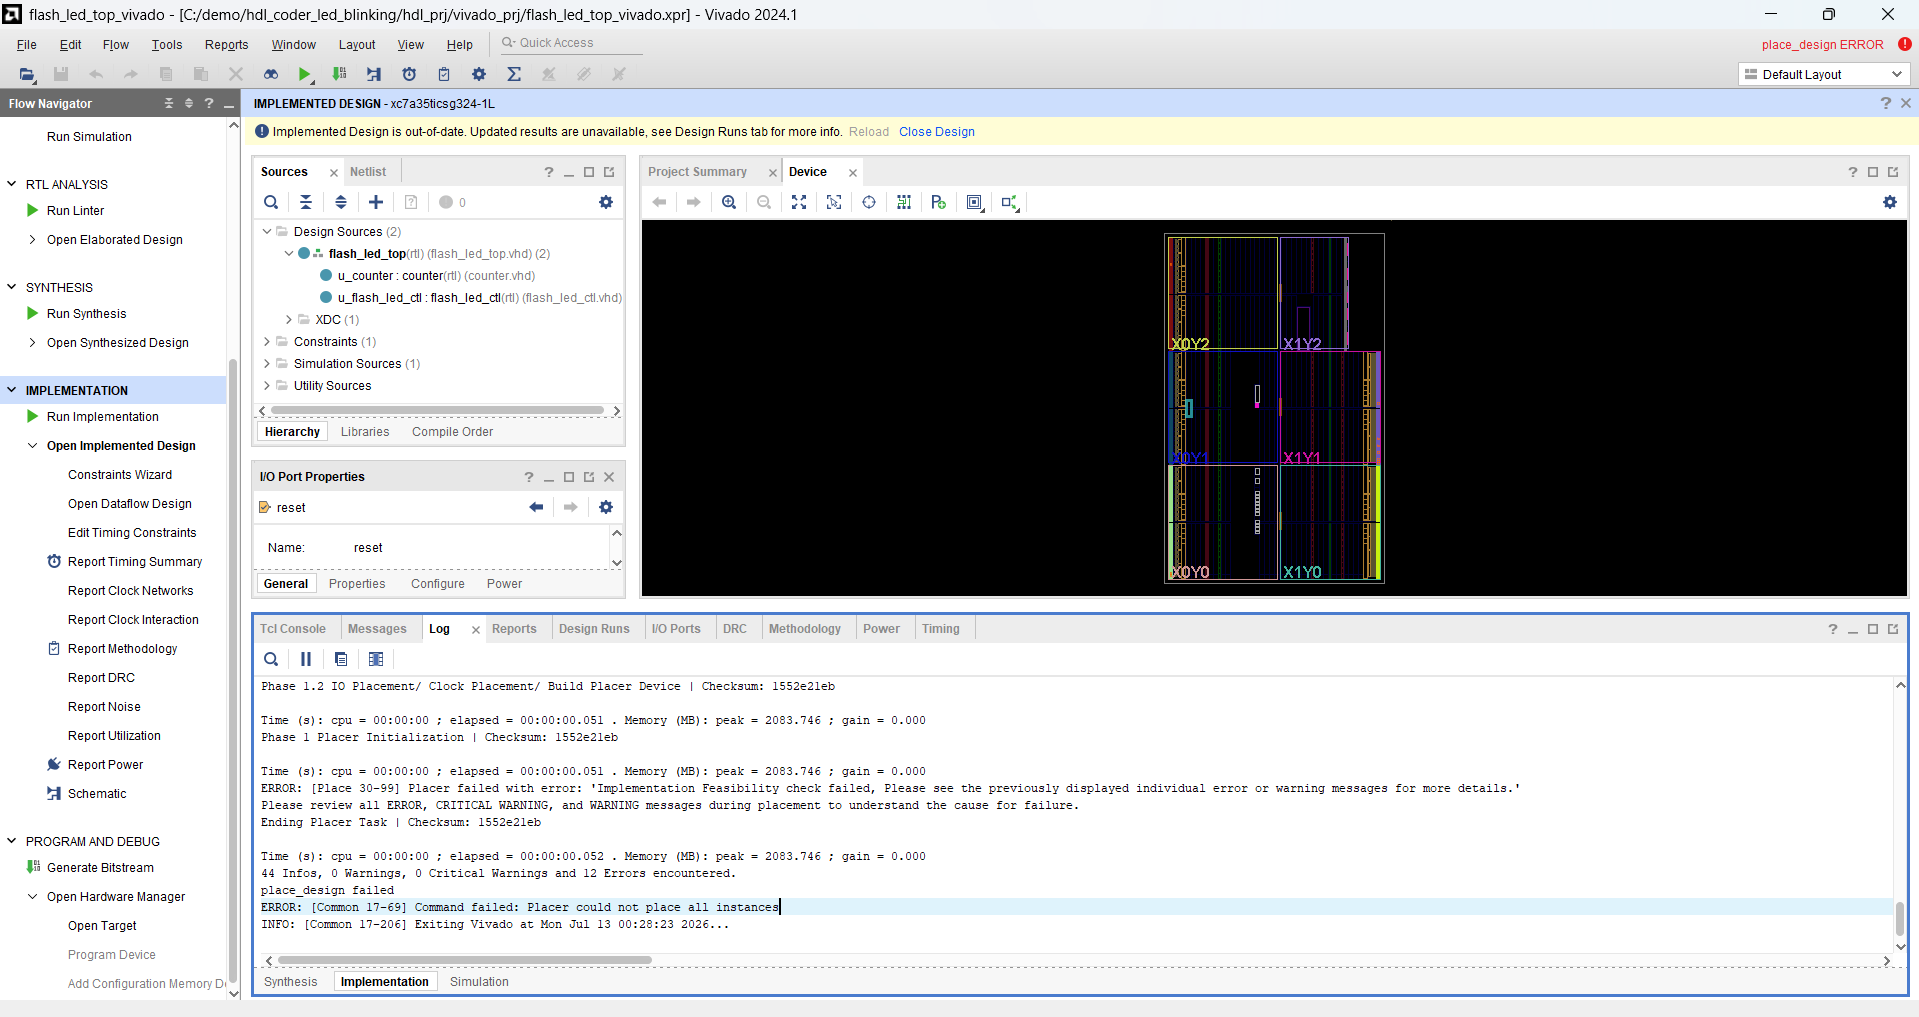

9.2 In the **Design Runs** tab, right-click **synth_1** and choose **Change Run Settings...**

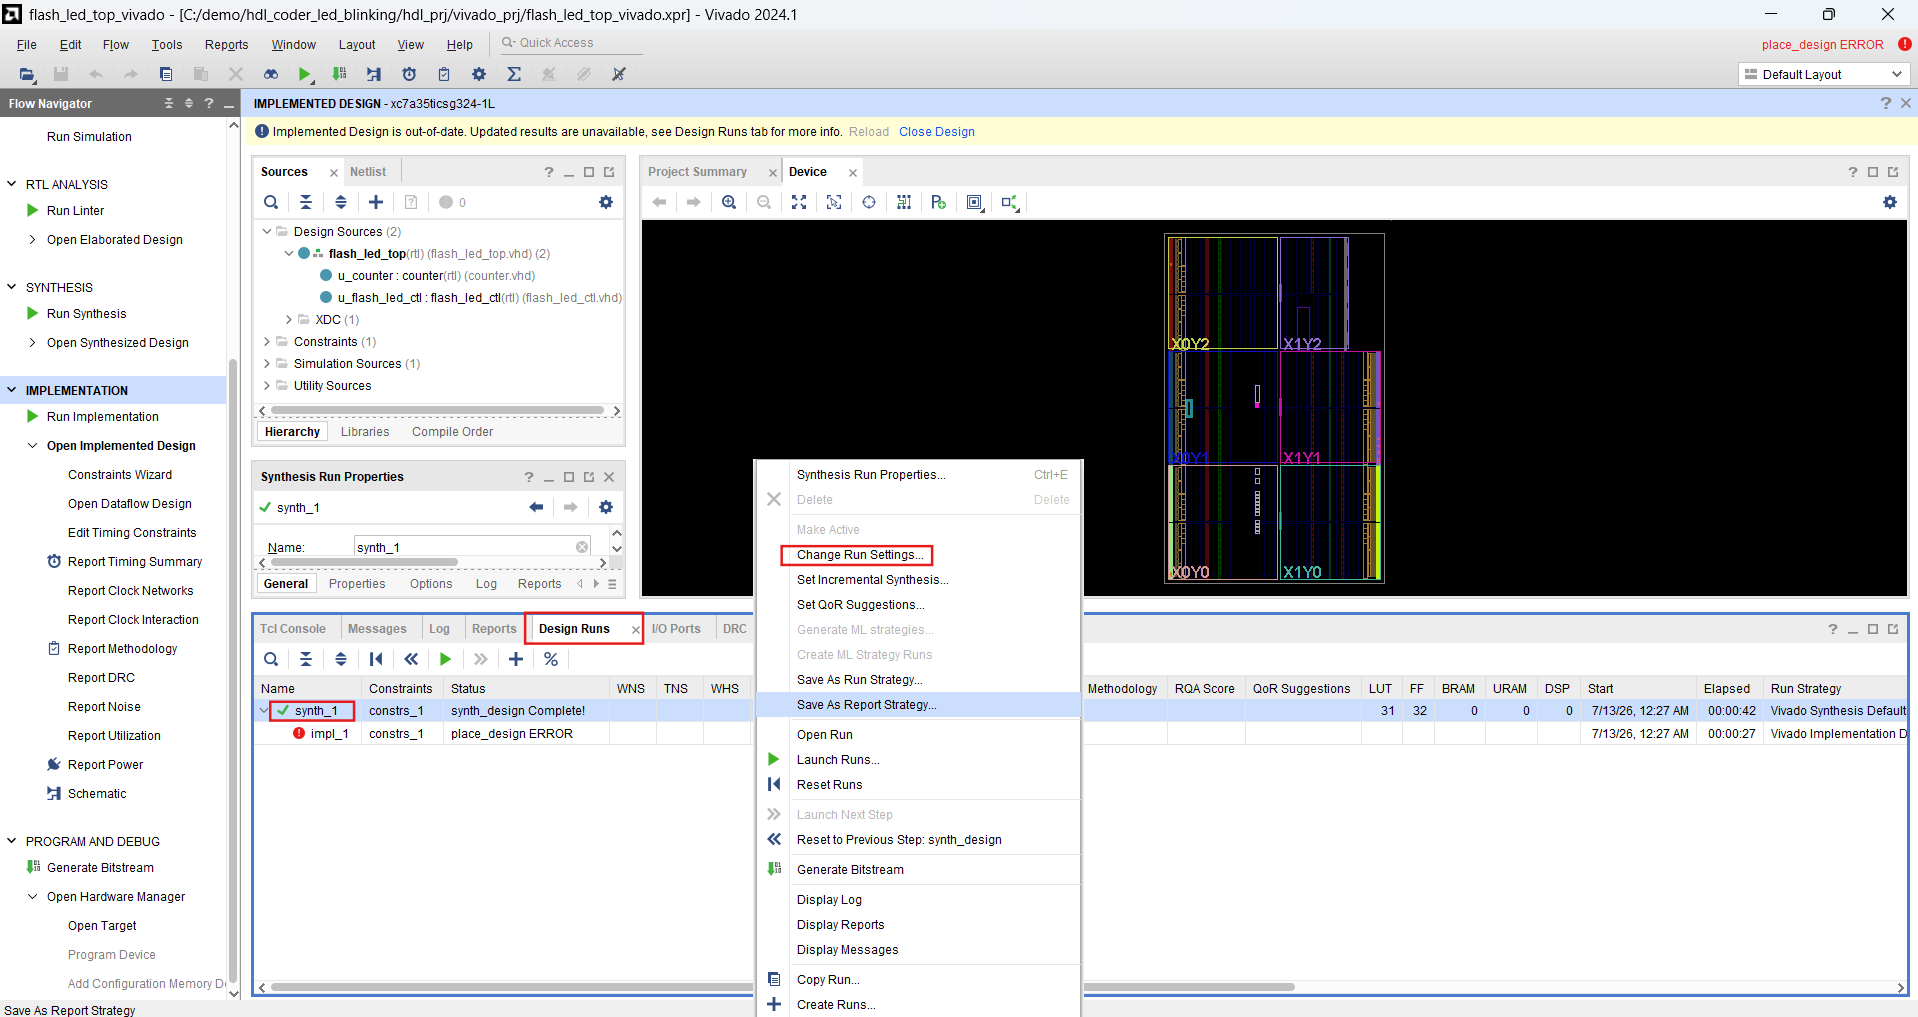

9.3 The **More Options** field at the bottom of the dialog contains `-mode out_of_context`:

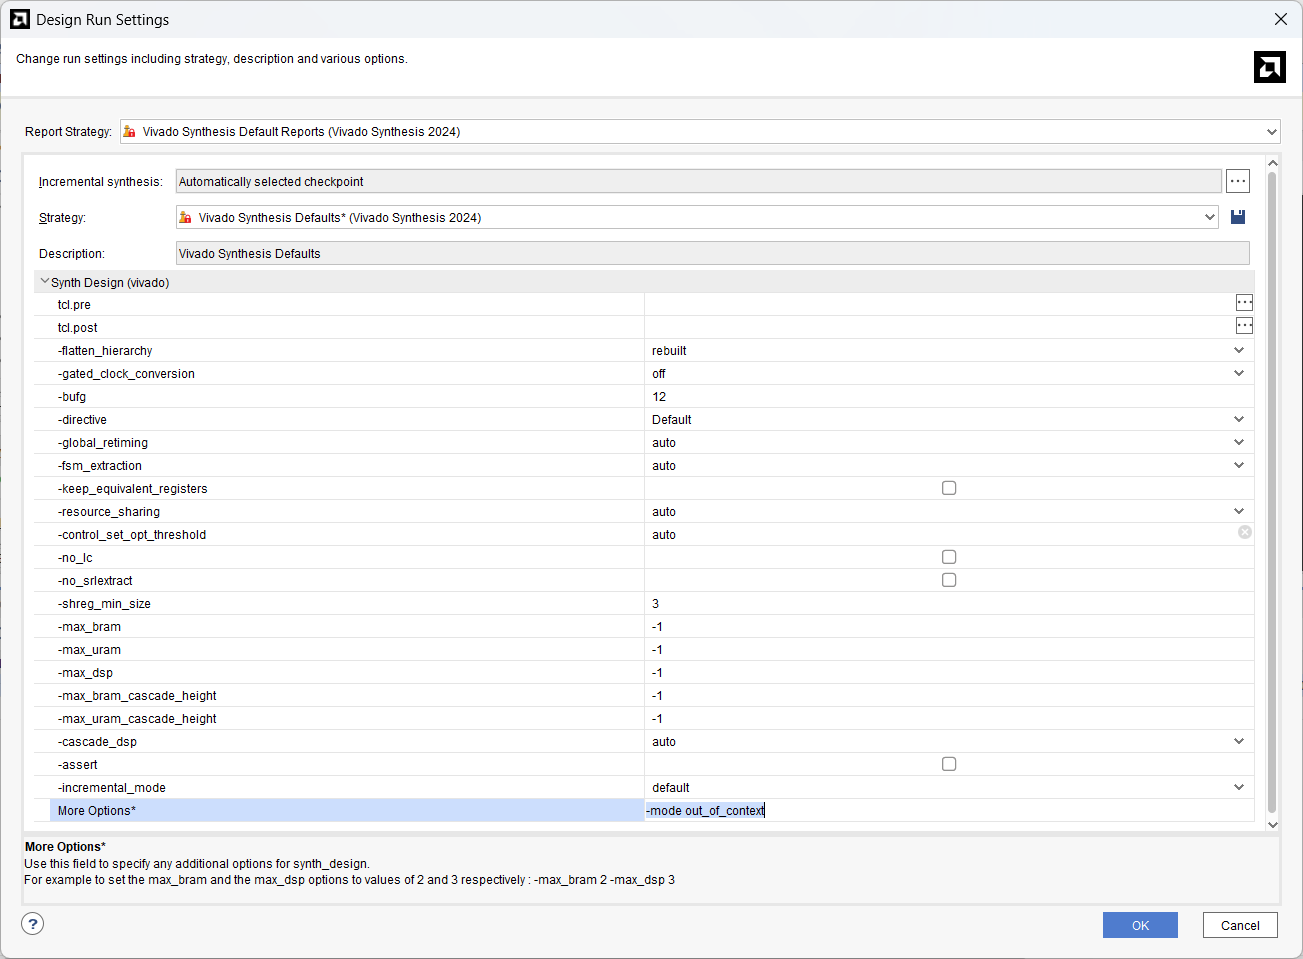

9.4 Delete the text so the field is empty, then click **OK**.

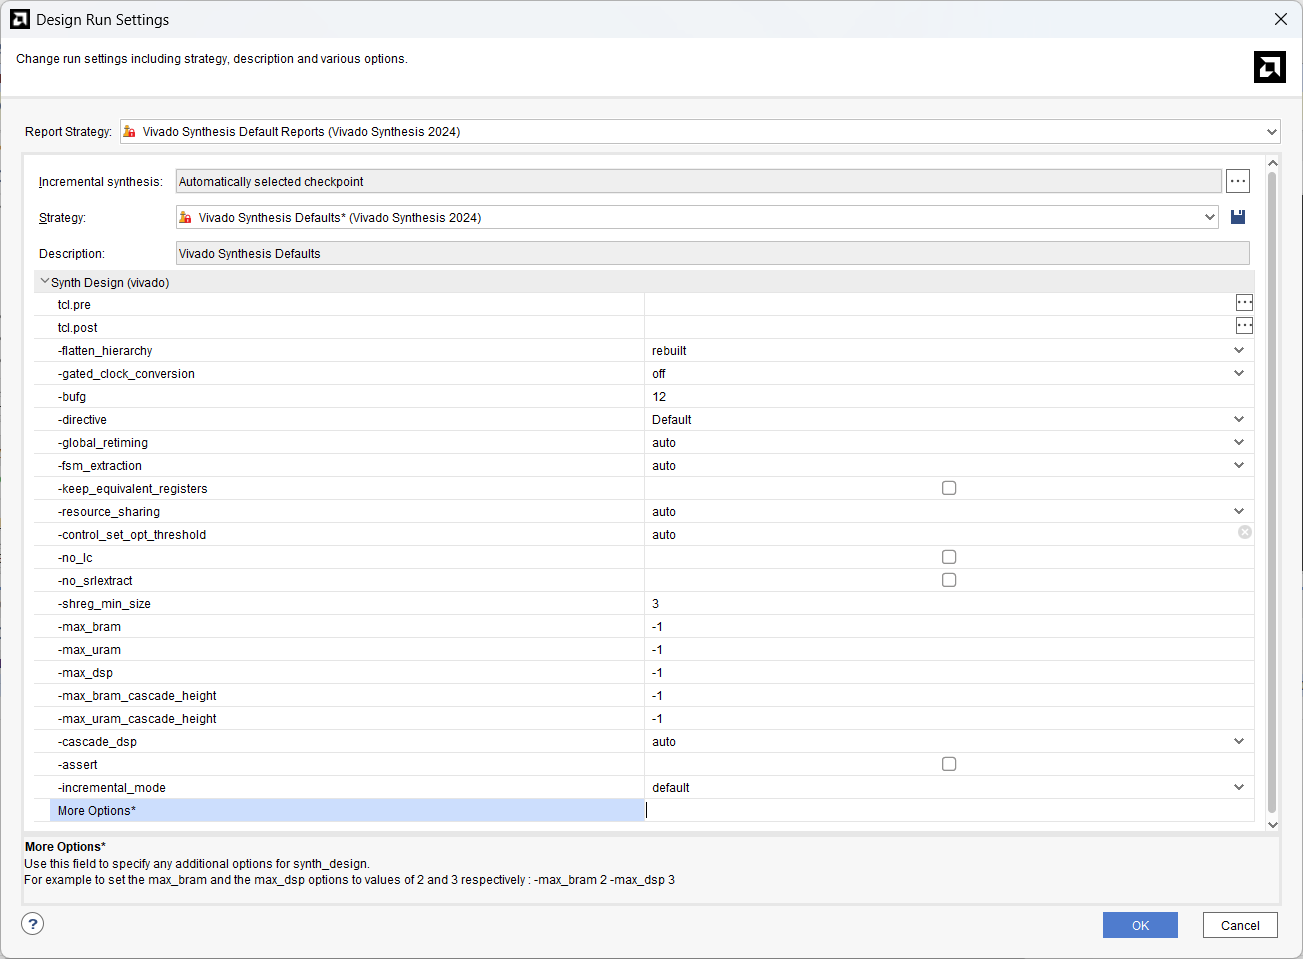

9.5 Right-click **synth_1** again and choose **Reset Runs** so the next build starts clean.

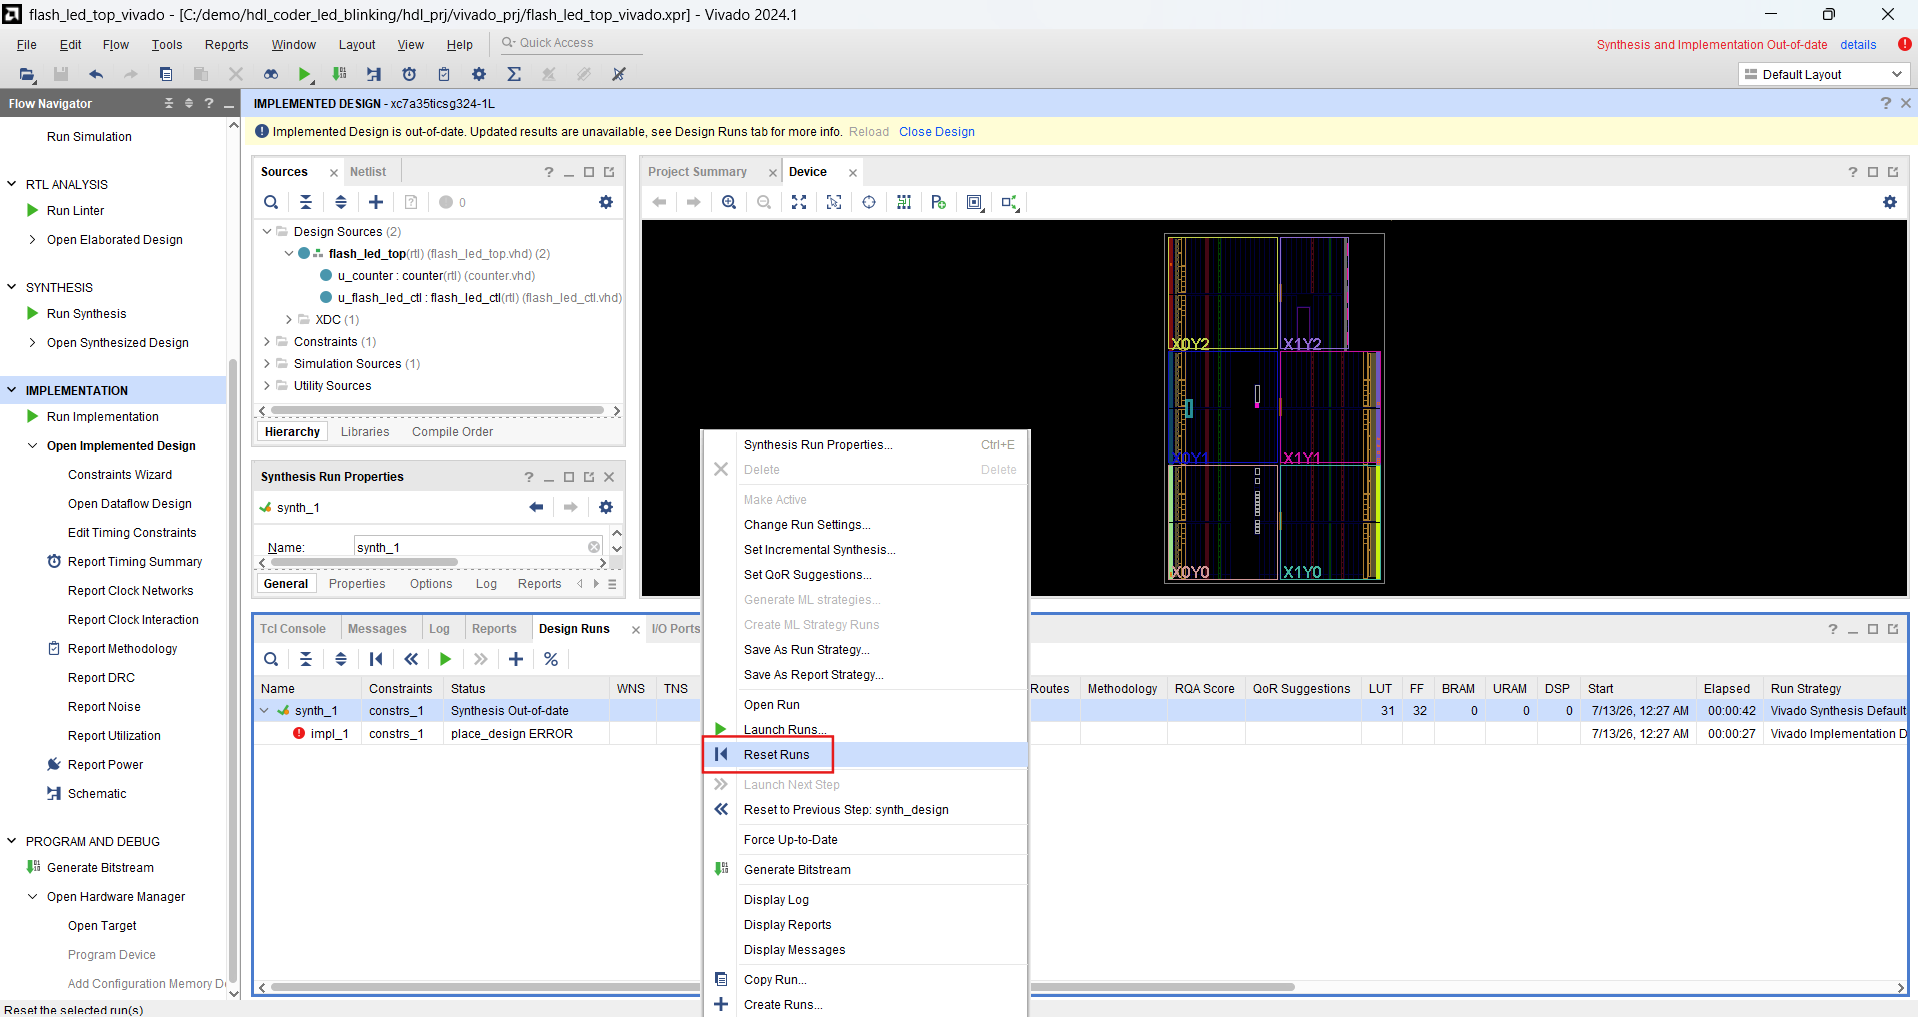

The Tcl Console equivalent of 9.2-9.5 is: `set_property -name {STEPS.SYNTH_DESIGN.ARGS.MORE OPTIONS} -value {} -objects [get_runs synth_1]` followed by `reset_run synth_1`.

## 10. Generate the bitstream

10.1 In the Flow Navigator click **Generate Bitstream** (under *Program and Debug*). Vivado re-runs synthesis - now as a full-design run with I/O buffers - then implementation, and writes the bitstream. When it finishes, choose **Open Hardware Manager** in the completion dialog.

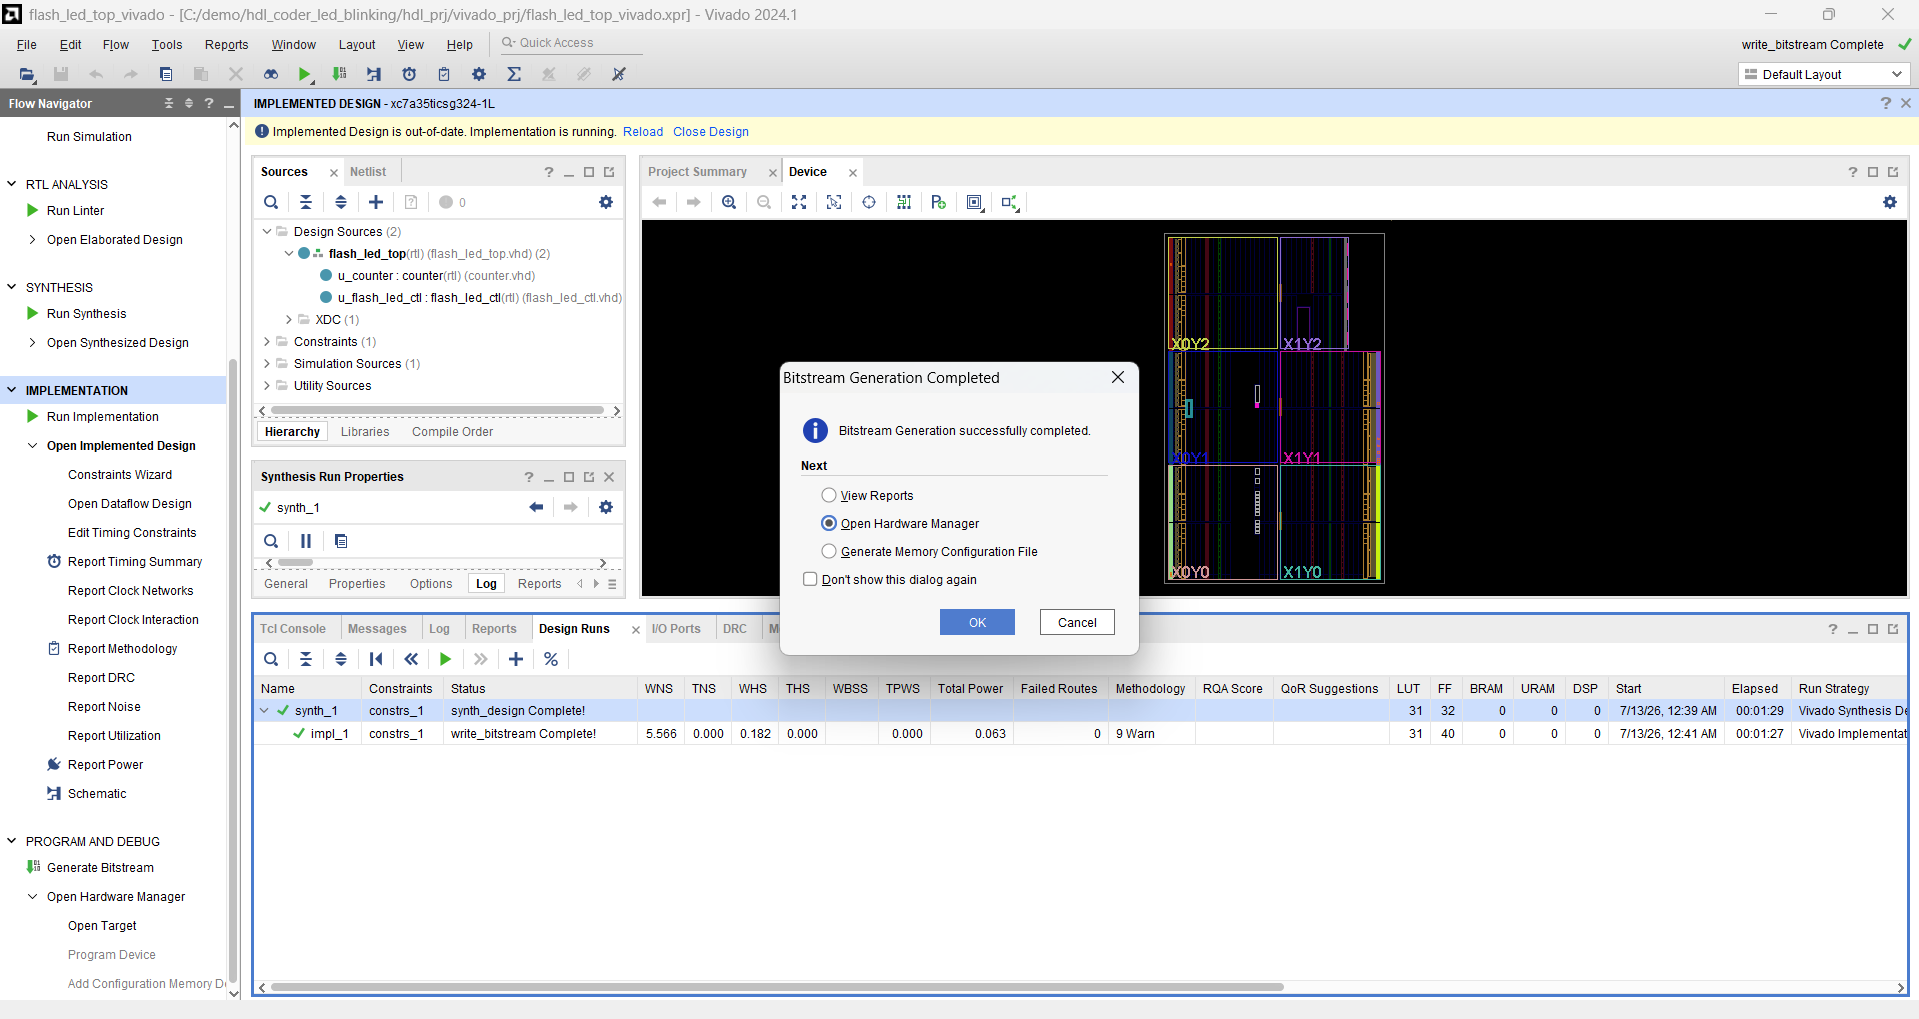

## 11. Program the board

11.1 With the Hardware Manager open (Flow Navigator > **Open Hardware Manager** if you closed the dialog), click **Open Target > Auto Connect**. Vivado connects to the Arty's USB-JTAG interface and the device `xc7a35t_0` appears in the Hardware tree.

11.2 Right-click `xc7a35t_0` and choose **Program Device...**

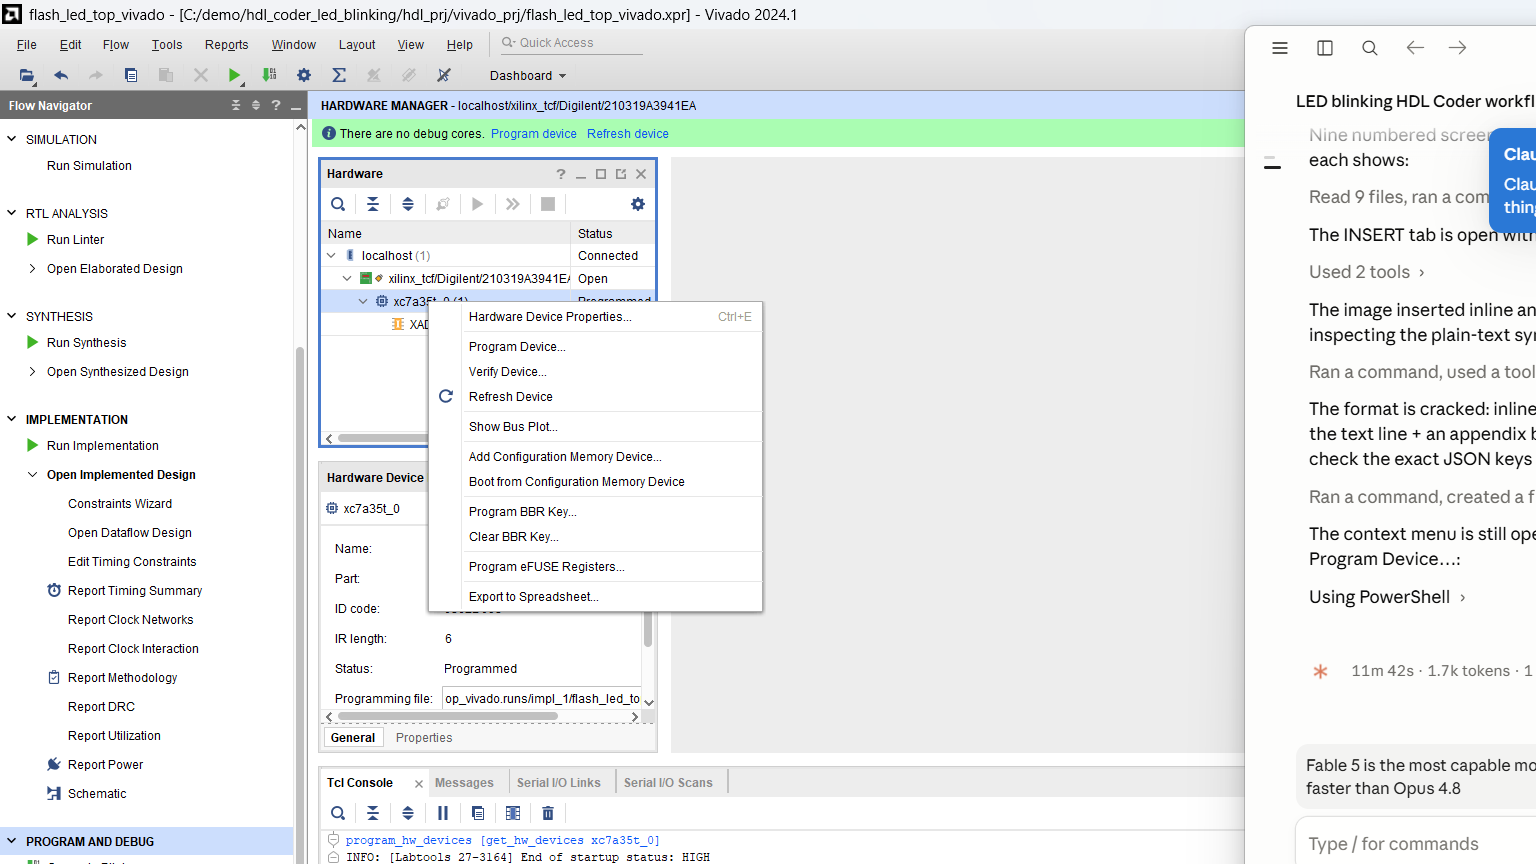

11.3 The bitstream file is prefilled with `...\flash_led_top_vivado.runs\impl_1\flash_led_top.bit`. Click **Program**.

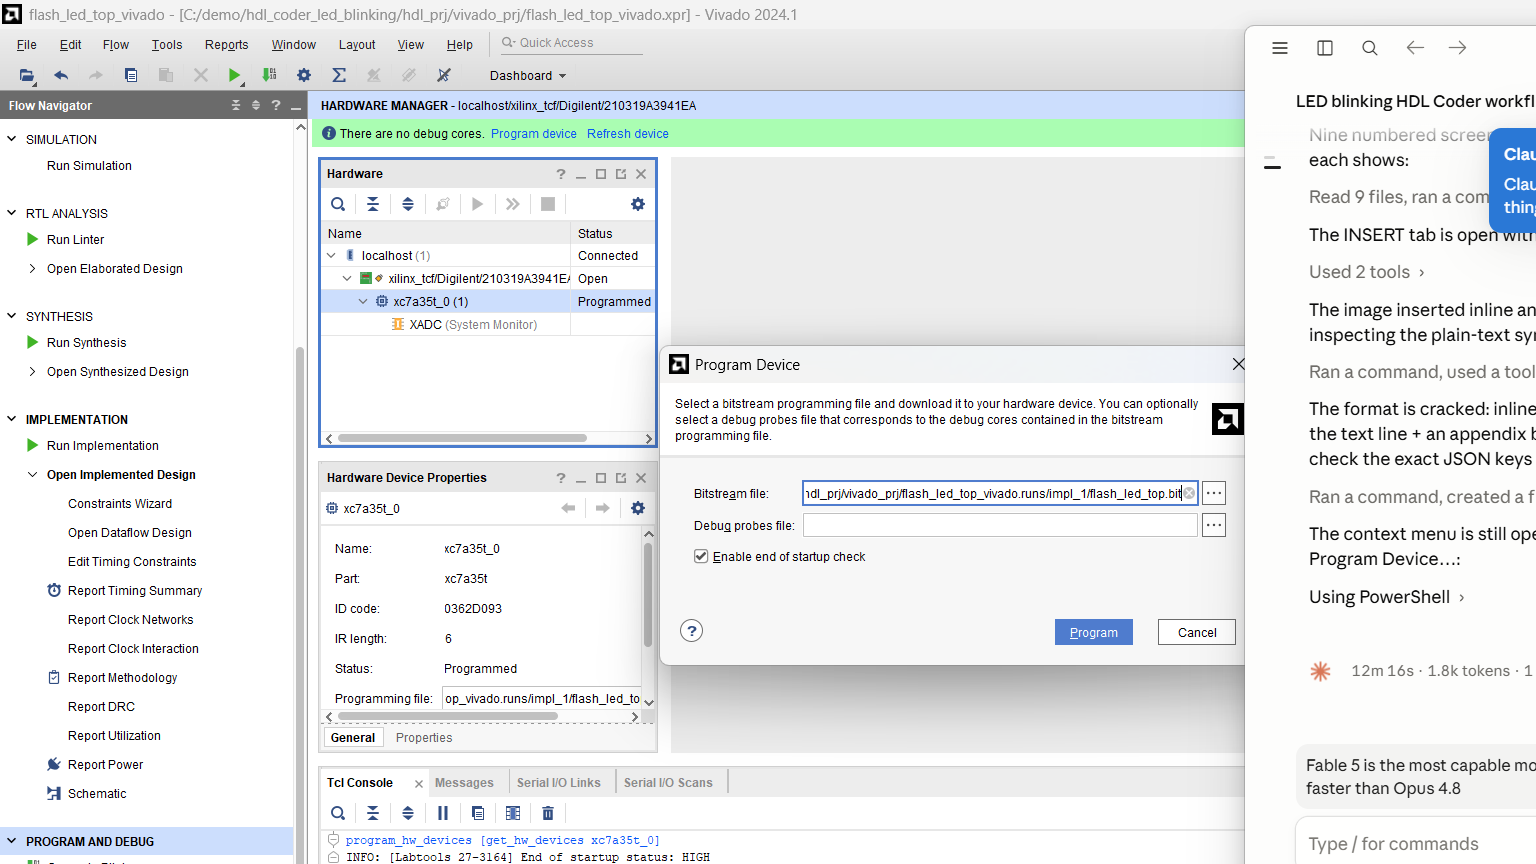

11.4 The device status changes to *Programmed* and the Tcl Console reports `End of startup status: HIGH` - the DONE LED lights and the design starts immediately.

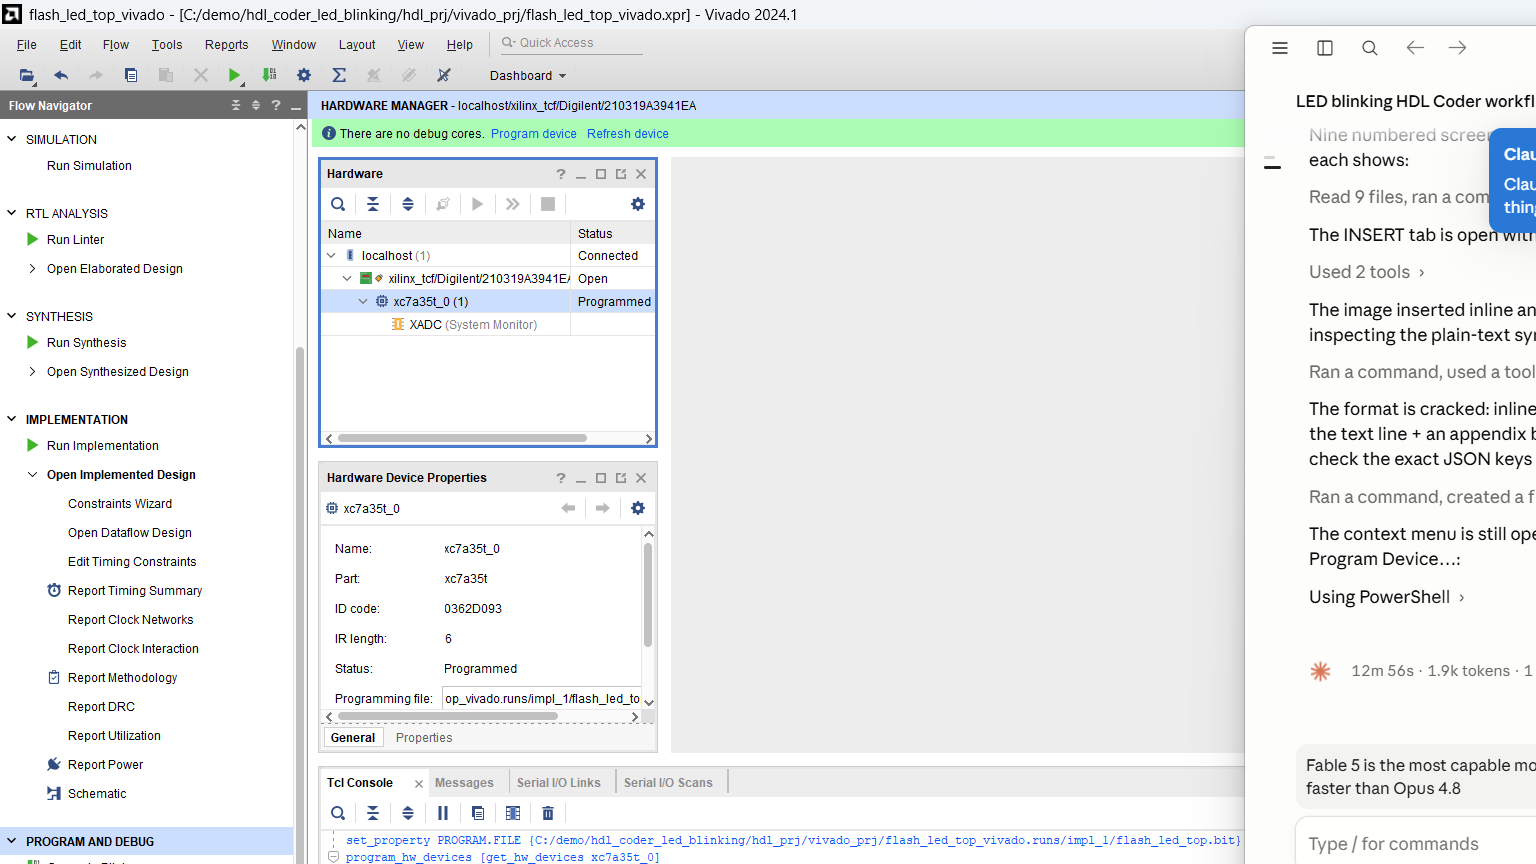

The Tcl Console equivalent, useful for scripting: `open_hw_manager`, `connect_hw_server`, `open_hw_target`, then `set_property PROGRAM.FILE {<path to .bit>} [get_hw_devices xc7a35t_0]` and `program_hw_devices [get_hw_devices xc7a35t_0]`.

## 12. Observe the result

A single lit LED sweeps across the eight LEDs - from LD4 through LD7 (green LEDs) and on through the green channels of the RGB LEDs LD0..LD3 - then wraps around, 20 steps per second (one full sweep every 0.4 s). Hold push button **BTN0** to reset the pattern back to LED0. This matches the behaviour of the hand-written VHDL reference design bit for bit: same clock divider, same registered tick, same rotate-left pattern.

**Where everything lives**

- `flash_led.slx` - the Simulink model (DUT: `flash_led_top`)

- `hdl_prj\hdlsrc\flash_led` - generated VHDL and code generation reports

- `hdl_prj\vivado_prj` - Vivado project, synthesis/implementation runs and bitstream

- `docs\images` - the screenshots used in this lab

## 13. Optional: register the Arty as a custom board

Sections 8-11 exist only because the Generic ASIC/FPGA workflow does not know the Arty board. If you register the Arty as a **custom board**, HDL Coder generates the pin constraints from the board definition and the **IP Core Generation** workflow runs all the way through to programming - no manual I/O Ports step (section 8), no out-of-context fix (section 9), and JTAG programming becomes a workflow task (sections 10-11). A complete, ready-to-use registration is provided in the `arty_custom_board` folder next to this guide, modeled on the plugin MathWorks ships for its own boards (`matlabroot\toolbox\hdlcoder\boards\amd\+XilinxArty`).

### 13.1 What is in the folder

- `hdlcoder_board_customization.m` - registration entry point; must be on the MATLAB path

- `+ArtyA7Custom\plugin_board.m` - an `hdlcoder.Board` object: device `xc7a35ti-csg324 -1L` plus the LED / push-button / slide-switch I/O interfaces with their Arty pins

- `+ArtyA7Custom\hdlcoder_ref_design_customization.m` - registers the reference design for this board

- `+ArtyA7Custom\+vivado_no_axi\plugin_rd.m` - an `hdlcoder.ReferenceDesign` (no processor, no AXI): a Clocking Wizard makes the DUT clock and a Processor System Reset makes the synchronized reset

- `+ArtyA7Custom\+vivado_no_axi\system_top.tcl` - the Vivado block design (clock wizard + reset)

- `+ArtyA7Custom\+vivado_no_axi\arty_clock_constraints.xdc` - the board clock (E3) and reset (BTN0/D9) pins

### 13.2 Put the board plugin on the MATLAB path

Add the folder to the path (put this line in your `startup.m` to make it permanent), then construct and validate the board object. `validateBoard` returning without error confirms HDL Coder accepts the registration. After adding the path for the first time, restart MATLAB (or run `rehash toolboxcache`) so the *Target platform* list in the Workflow Advisor picks up the new board.

addpath(fullfile(projDir,'arty_custom_board'))
hB = ArtyA7Custom.plugin_board();
hB.validateBoard();
disp(hB.BoardName)

Digilent Arty A7-35T (custom)


### 13.3 The interfaces the board exposes

`plugin_board.m` maps each named board interface to its Arty pins (from the Digilent master XDC, all LVCMOS33). BTN0 (D9) is deliberately *not* a push-button interface here - the reference design uses it as the system reset.

### 13.4 Point the model at the custom board (Set Target Interface)

In the HDL Workflow Advisor, task **1.1** now lists **Digilent Arty A7-35T (custom)** in the *Target platform* dropdown, task **1.2** offers the *Default system (no AXI)* reference design, and a new **Set Target Interface** task appears where you map the DUT `led` port to the board LED bank. That mapping is what replaces the manual pin assignment of section 8. The equivalent commands (they only change model settings) are:

- `hdlset_param('flash_led','Workflow','IP Core Generation')`

- `hdlset_param('flash_led','TargetPlatform','Digilent Arty A7-35T (custom)')`

- `hdlset_param('flash_led','ReferenceDesign','Default system (no AXI)')`

- `hdlset_param('flash_led','TargetFrequency',100)`

- `hdlset_param('flash_led/flash_led_top/led','IOInterface','LEDs General Purpose [0:7]')`

If `TargetPlatform` reports an *Invalid value* error, the platform list was cached before the folder was on the path - restart MATLAB with the `addpath` in your `startup.m` and set it again.

### 13.5 Run the workflow to a programmed board

With the board and interface set, run the IP Core Generation workflow. It builds the block design (clock wizard + reset), packages the DUT as an IP core, **generates the pin constraints from the board definition** (no hand-written XDC), builds the bitstream and programs the Arty. The build takes several minutes, so run it deliberately from the Workflow Advisor, or from the command line with:

- `hWC = hdlcoder.WorkflowConfig('SynthesisTool','Xilinx Vivado','TargetWorkflow','IP Core Generation');`

- `hWC.ProjectFolder = 'hdl_prj_ipcore';`

- `hWC.RunTaskGenerateSoftwareInterface = false;` (no embedded processor)

- `hWC.RunTaskProgramTargetDevice = true;` (JTAG programming)

- `hdlcoder.runWorkflow('flash_led/flash_led_top', hWC);`

During **Create Project**, HDL Coder writes a constraints file straight from the board definition. For this design it contains exactly the eight LED pins - the same mapping section 8 did by hand: `set_property PACKAGE_PIN H5 [get_ports {GPLEDs[0]}]` through `set_property PACKAGE_PIN H6 [get_ports {GPLEDs[7]}]`, each with `IOSTANDARD LVCMOS33`.

### 13.6 What the custom board changes

- **Section 8 (pin assignment) disappears** - the pin locations and I/O standards come from `plugin_board.m` and are written into the project automatically during Create Project.

- **Section 9 (out-of-context fix) disappears** - IP Core Generation builds a full block-design project that already has I/O buffers, so there is no placer failure.

- **Sections 10-11 (bitstream + programming) become workflow tasks** - *Build FPGA Bitstream* and *Program Target Device* run from the advisor.

Two things to keep in mind. The *Target Frequency* reconfigures the reference design's Clocking Wizard, so the DUT clock really runs at 100 MHz. And if the *Program Target Device* task fails with a Xilinx `EXCEPTION_ACCESS_VIOLATION` from the JTAG server (an environmental crash of `hw_server`/`cs_server` seen on some machines), the bitstream is still valid - program it from the Vivado Hardware Manager exactly as in section 11, pointing at `hdl_prj_ipcore\vivado_ip_prj\vivado_prj.runs\impl_1\system_top_wrapper.bit`.

Because section 13.4 above only prints the equivalent commands, the model in this notebook stays on the Generic ASIC/FPGA flow of sections 1-12 - nothing to undo.